ryan3_1_chargePattern_RUL.mlx (epoc_count = 2;) 와의 차이는 epoc_count = 10; 으로 설정해서 좀 더 학습을 더 한것이다.

clc; 
clear ;
close all;

tic
load ryan3_gen_data.mat
toc 

Elapsed time is 13.205166 seconds.


% https://kr.mathworks.com/help/matlab/ref/load.html
%load('ryan3_gen_data.mat','battery_dataset')

# 변수 추출

cap = zeros();
Vd = zeros();
RUL = zeros();
%Vd = [1:100];
battery_dataset(1).QDischargeSmooth

ans =     1.0479
    1.0478
    1.0477
    1.0476
    1.0475
    1.0474
    1.0473
    1.0472
    1.0471
    1.0470


battery_dataset(1).Vd

ans =     2.0166    3.2957    3.2329    3.2020    3.1854    3.1754    3.1689    3.1642    3.1605    3.1572    3.1545    3.1518    3.1495    3.1474    3.1452    3.1431    3.1411    3.1390    3.1368    3.1348    3.1327    3.1306    3.1286    3.1265    3.1243    3.1220    3.1199    3.1175    3.1152    3.1127    3.1103    3.1079    3.1052    3.1028    3.1002    3.0975    3.0949    3.0921    3.0895    3.0866    3.0838    3.0809    3.0780    3.0750    3.0719    3.0687    3.0654    3.0621    3.0585    3.0549
    2.0161    3.2949    3.2324    3.2014    3.1848    3.1749    3.1686    3.1637    3.1599    3.1568    3.1540    3.1515    3.1492    3.1469    3.1448    3.1427    3.1407    3.1386    3.1365    3.1345    3.1325    3.1304    3.1283    3.1262    3.1239    3.1217    3.1195    3.1171    3.1148    3.1125    3.1101    3.1076    3.1050    3.1025    3.0999    3.0972    3.0947    3.0919    3.0891    3.0863    3.0836    3.0806    3.0777    3.0747    3.0716    3.0684    3.0652    3.0619    3.0582   

size(battery_dataset(1).QDischargeSmooth)

ans =    428     1


length(battery_dataset(1).QDischargeSmooth)

ans = 428


idxAll = (1:length(battery_dataset));
idxTrainValid = [ idxTrain idxValid ];
idxTrainAll = []; %zeros();
idxValidAll = []; %zeros();
idxTestAll = []; %zeros();


j =1;
startIndx = j ;
GenerateFrameList = @(A,S,N) A+S*(0:N-1);

for i = 1: length(idxAll)
        
    cap_temp = battery_dataset(i).QDischargeSmooth;
    RUL_temp = linspace(battery_dataset(i).cycle_life,1,battery_dataset(i).cycle_life)';
    leng = length(cap_temp);
    %startIndx = j ;
    % https://kr.mathworks.com/matlabcentral/answers/478553-how-can-i-have-a-starting-number-a-step-size-then-the-number-of-numbers-i-need-in-a-1d-array
    append_index = GenerateFrameList(startIndx,1,leng);
    
    Vd_temp = battery_dataset(i).Vd ;
    Ic_temp = battery_dataset(i).Ic ;
    %Vd = [Vd ; Vd_temp];
    if  i == 1
        Vd = Vd_temp;
        cap = cap_temp; 
        Ic = Ic_temp;
        RUL = RUL_temp;
    else
        Vd = vertcat(Vd,Vd_temp);
        %cap = vertcat(cap,cap_temp);
        Ic = vertcat(Ic,Ic_temp);
        RUL = vertcat(RUL,RUL_temp);
    end
    
    if any(idxTrain(:) == i) 
       % https://kr.mathworks.com/matlabcentral/answers/283821-add-single-element-to-array-or-vector
       idxTrainAll =  [idxTrainAll append_index ] ;
    end
    if any(idxValid(:) == i) 
       idxValidAll =  [idxValidAll append_index ] ;
    end
    if any(idxTest(:) == i) 
       idxTestAll =  [idxTestAll append_index ] ;
    end
    %Vd(i) = Vd_temp;
    
    startIndx = startIndx + leng;
end


idxTrainAll

idxTrainAll =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idxValidAll

idxValidAll =         2793        2794        2795        2796        2797        2798        2799        2800        2801        2802        2803        2804        2805        2806        2807        2808        2809        2810        2811        2812        2813        2814        2815        2816        2817        2818        2819        2820        2821        2822        2823        2824        2825        2826        2827        2828        2829        2830        2831        2832        2833        2834        2835        2836        2837        2838        2839        2840        2841        2842


idxTestAll

idxTestAll =         4962        4963        4964        4965        4966        4967        4968        4969        4970        4971        4972        4973        4974        4975        4976        4977        4978        4979        4980        4981        4982        4983        4984        4985        4986        4987        4988        4989        4990        4991        4992        4993        4994        4995        4996        4997        4998        4999        5000        5001        5002        5003        5004        5005        5006        5007        5008        5009        5010        5011


cap

cap =     1.0479
    1.0478
    1.0477
    1.0476
    1.0475
    1.0474
    1.0473
    1.0472
    1.0471
    1.0470


Vd

Vd =     2.0166    3.2957    3.2329    3.2020    3.1854    3.1754    3.1689    3.1642    3.1605    3.1572    3.1545    3.1518    3.1495    3.1474    3.1452    3.1431    3.1411    3.1390    3.1368    3.1348    3.1327    3.1306    3.1286    3.1265    3.1243    3.1220    3.1199    3.1175    3.1152    3.1127    3.1103    3.1079    3.1052    3.1028    3.1002    3.0975    3.0949    3.0921    3.0895    3.0866    3.0838    3.0809    3.0780    3.0750    3.0719    3.0687    3.0654    3.0621    3.0585    3.0549
    2.0161    3.2949    3.2324    3.2014    3.1848    3.1749    3.1686    3.1637    3.1599    3.1568    3.1540    3.1515    3.1492    3.1469    3.1448    3.1427    3.1407    3.1386    3.1365    3.1345    3.1325    3.1304    3.1283    3.1262    3.1239    3.1217    3.1195    3.1171    3.1148    3.1125    3.1101    3.1076    3.1050    3.1025    3.0999    3.0972    3.0947    3.0919    3.0891    3.0863    3.0836    3.0806    3.0777    3.0747    3.0716    3.0684    3.0652    3.0619    3.0582    

Ic

Ic =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999
         0    4.3998    4.3999    4.4002    4.3997    4.4004    4.3997    4.4002    4.4000    4.4005    4.4002    4.3999    4.3995    4.4000    4.4001    4.3998    4.3999    4.4000    4.4001    4.3999    4.4015    4.3998    4.4000    4.4002    4.3999    4.4002    4.4000    4.4000    4.4002    4.4003    4.4000    4.3999    4.4001    4.4003    4.4000    4.3998    4.3999    4.3996    4.4003    4.3989    4.4000    4.4002    4.4000    4.3998    4.4000    4.4000    4.3999    4.4001    4.4002    

RUL

RUL =    428
   427
   426
   425
   424
   423
   422
   421
   420
   419


% https://kr.mathworks.com/matlabcentral/answers/80480-how-do-i-take-the-average-of-every-n-values-in-a-vector
blockSize = [1, 5] % 다섯개를 묶어서.

blockSize =      1     5


meanFilterFunction = @(theBlockStructure) mean2(theBlockStructure.data(:))

meanFilterFunction = function_handle with value:
    @(theBlockStructure)mean2(theBlockStructure.data(:))



Ic_new = blockproc(Ic, blockSize, meanFilterFunction)

Ic_new =     3.5201    4.4001    4.4002    4.4001    4.4000    4.3998    4.3999    4.3999    4.3999    4.4001    4.4000    4.4000    4.3999    4.4000    2.9013    1.0000    1.0000    0.0994         0         0
    3.5199    4.4002    4.3999    4.3999    4.4003    4.4001    4.4001    4.3997    4.4000    4.4001    4.3999    4.4002    4.4000    4.2403    2.9039    1.0001    1.0000    0.0985         0         0
    3.5200    4.4000    4.3998    4.4000    4.3999    4.4000    4.4001    4.3999    4.4000    4.4000    4.3999    4.3999    4.3999    4.4000    2.8984    1.0000    1.0000    0.0986         0         0
    3.5198    4.4000    4.4000    4.4000    4.4001    4.4001    4.4000    4.3999    4.4000    4.4001    4.4001    4.4000    4.4002    4.1381    2.8975    0.9998    0.9999    0.0946         0         0
    3.5200    4.4001    4.4001    4.4000    4.4001    4.3999    4.4000    4.4000    4.4000    4.4000    4.3996    4.4000    4.3997    4.3998    2.8970    0.9998    1.0000    0.0949       

%clear Ic  

Vd_new = blockproc(Vd, blockSize, meanFilterFunction)

Vd_new =     2.9865    3.1652    3.1497    3.1389    3.1285    3.1174    3.1053    3.0921    3.0779    3.0619    3.0428    3.0185    2.9853    2.9360    2.8528    2.6893    2.2963    1.9998    1.9998    1.9998
    2.9859    3.1648    3.1493    3.1386    3.1282    3.1171    3.1050    3.0918    3.0776    3.0616    3.0425    3.0182    2.9851    2.9357    2.8525    2.6892    2.2980    1.9999    1.9999    1.9999
    2.9866    3.1656    3.1499    3.1392    3.1287    3.1175    3.1054    3.0922    3.0779    3.0619    3.0428    3.0184    2.9853    2.9359    2.8522    2.6877    2.2909    2.0001    2.0001    2.0001
    2.9862    3.1650    3.1495    3.1388    3.1283    3.1172    3.1051    3.0919    3.0776    3.0617    3.0425    3.0182    2.9850    2.9355    2.8519    2.6878    2.2935    1.9997    1.9996    1.9996
    2.9862    3.1649    3.1494    3.1387    3.1283    3.1173    3.1051    3.0919    3.0778    3.0618    3.0426    3.0183    2.9851    2.9357    2.8521    2.6878    2.2933    2.0001    2.0

%clear Vd  

save('ryan3_gen_data.mat','Ic_new','-append');
save('ryan3_gen_data.mat','Vd_new','-append');
save('ryan3_gen_data.mat','cap','-append');
save('ryan3_gen_data.mat','Ic','-append');
save('ryan3_gen_data.mat','Vd','-append');
save('ryan3_gen_data.mat','idxTrainAll','-append');
save('ryan3_gen_data.mat','idxValidAll','-append');
save('ryan3_gen_data.mat','idxTestAll','-append');
save('ryan3_gen_data.mat','RUL','-append');


%x = Vd_new;
x = Ic_new;
y = RUL;
[ynorm,ymax,ymin,yrate,xnorm,xmax,xmin,xrate] = minmax_norm_new(y,x);



clear Ic Vd
clear Ic_new Vd_new 
clear battery_dataset

# 학습/검증 및 테스트 데이타 추출

x_trainValid = xnorm([idxTrainAll idxValidAll],:)

x_trainValid =     0.4398    0.5497    0.5498    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.5498    0.5497    0.5497    0.5497    0.5497    0.3625    0.1249    0.1249    0.0124         0         0
    0.4398    0.5498    0.5497    0.5497    0.5498    0.5498    0.5497    0.5497    0.5497    0.5497    0.5497    0.5498    0.5497    0.5298    0.3628    0.1250    0.1249    0.0123         0         0
    0.4398    0.5497    0.5497    0.5497    0.5497    0.5497    0.5498    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.3621    0.1249    0.1249    0.0123         0         0
    0.4398    0.5497    0.5497    0.5497    0.5497    0.5498    0.5497    0.5497    0.5497    0.5498    0.5497    0.5497    0.5498    0.5170    0.3620    0.1249    0.1249    0.0118         0         0
    0.4398    0.5497    0.5498    0.5497    0.5498    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.3620    0.1249    0.1249    0.0119 

x_test = xnorm([idxTestAll],:)

x_test =     0.5997    0.7497    0.7496    0.7497    0.7496    0.7497    0.7496    0.5247    0.3748    0.3748    0.3748    0.3748    0.3748    0.3748    0.2749    0.1249    0.1250    0.0132         0         0
    0.5998    0.7497    0.7496    0.7496    0.7496    0.7497    0.7496    0.5247    0.3748    0.3748    0.3748    0.3748    0.3748    0.3748    0.2749    0.1249    0.1249    0.0130         0         0
    0.5997    0.7496    0.7497    0.7497    0.7497    0.7496    0.7497    0.5248    0.3748    0.3748    0.3748    0.3748    0.3748    0.3748    0.2749    0.1249    0.1249    0.0128         0         0
    0.5998    0.7497    0.7496    0.7496    0.7497    0.7497    0.7497    0.5247    0.3748    0.3748    0.3748    0.3748    0.3748    0.3748    0.2748    0.1249    0.1249    0.0124         0         0
    0.5998    0.7496    0.7497    0.7497    0.7496    0.7496    0.7497    0.5247    0.3748    0.3748    0.3748    0.3748    0.3748    0.3748    0.2749    0.1249    0.1249    0.0123       


y_trainValid = ynorm([idxTrainAll idxValidAll])

y_trainValid =     0.3650
    0.3641
    0.3632
    0.3624
    0.3615
    0.3607
    0.3598
    0.3590
    0.3581
    0.3573


y_test = ynorm([idxTestAll])

y_test =     0.2692
    0.2684
    0.2675
    0.2667
    0.2658
    0.2650
    0.2641
    0.2632
    0.2624
    0.2615


# 선형회귀

tic
mdl = fitlm(x_trainValid,y_trainValid)

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20

Estimated Coefficients:
                   Estimate        SE         tStat       pValue   
                   _________    _________    _______    ___________

    (Intercept)      0.35169    0.0097665      36.01    2.7133e-279
    x1             -0.047798     0.014404    -3.3185     0.00090601
    x2             -0.032413     0.018185    -1.7824       0.074688
    x3              -0.21615     0.017472    -12.371     4.3618e-35
    x4               0.16227     0.014826     10.945     7.7348e-28
    x5              -0.21989     0.019736    -11.141     8.7442e-29
    x6             -0.0

toc

Elapsed time is 3.136954 seconds.



coeff = mdl.Coefficients.Estimate

coeff =     0.3517
   -0.0478
   -0.0324
   -0.2161
    0.1623
   -0.2199
   -0.0569
   -0.0843
    0.2115
   -0.2393


x_trainValid(1,:)

ans =     0.4398    0.5497    0.5498    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.5498    0.5497    0.5497    0.5497    0.5497    0.3625    0.1249    0.1249    0.0124         0         0


training set 에서는 정말 잘 동작함.

RMSE 가 정말 작다.

yhat = x_trainValid*coeff(2:21)+coeff(1)

yhat =     0.4490
    0.4577
    0.4475
    0.4580
    0.4433
    0.4403
    0.4403
    0.4385
    0.4368
    0.4355


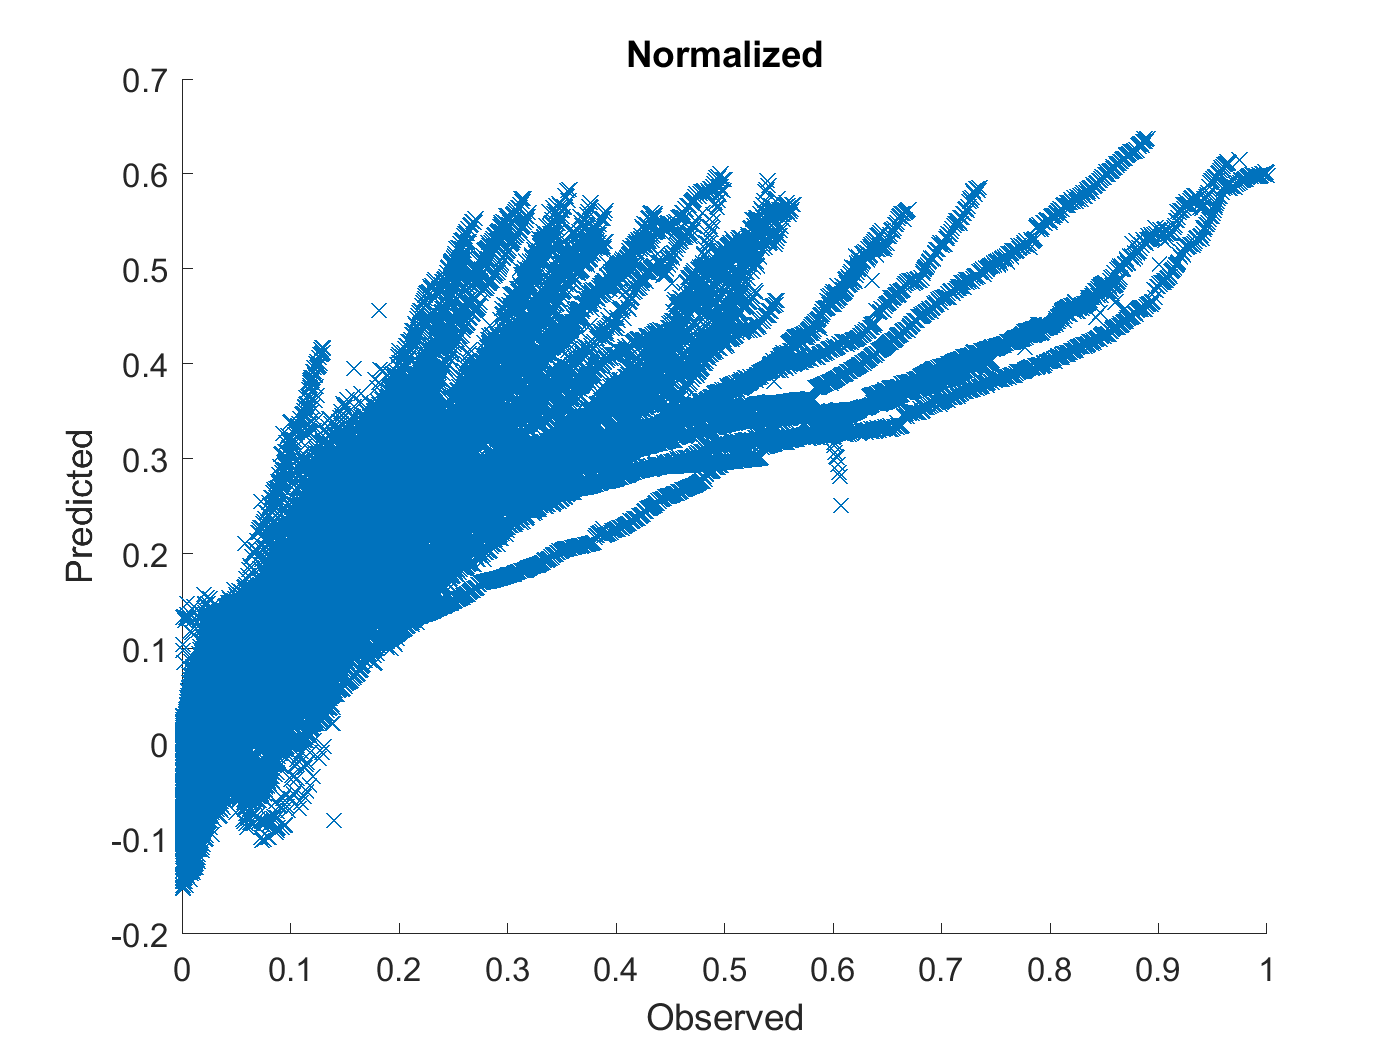

figure
hold on
plot(y_trainValid,yhat,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Normalized'

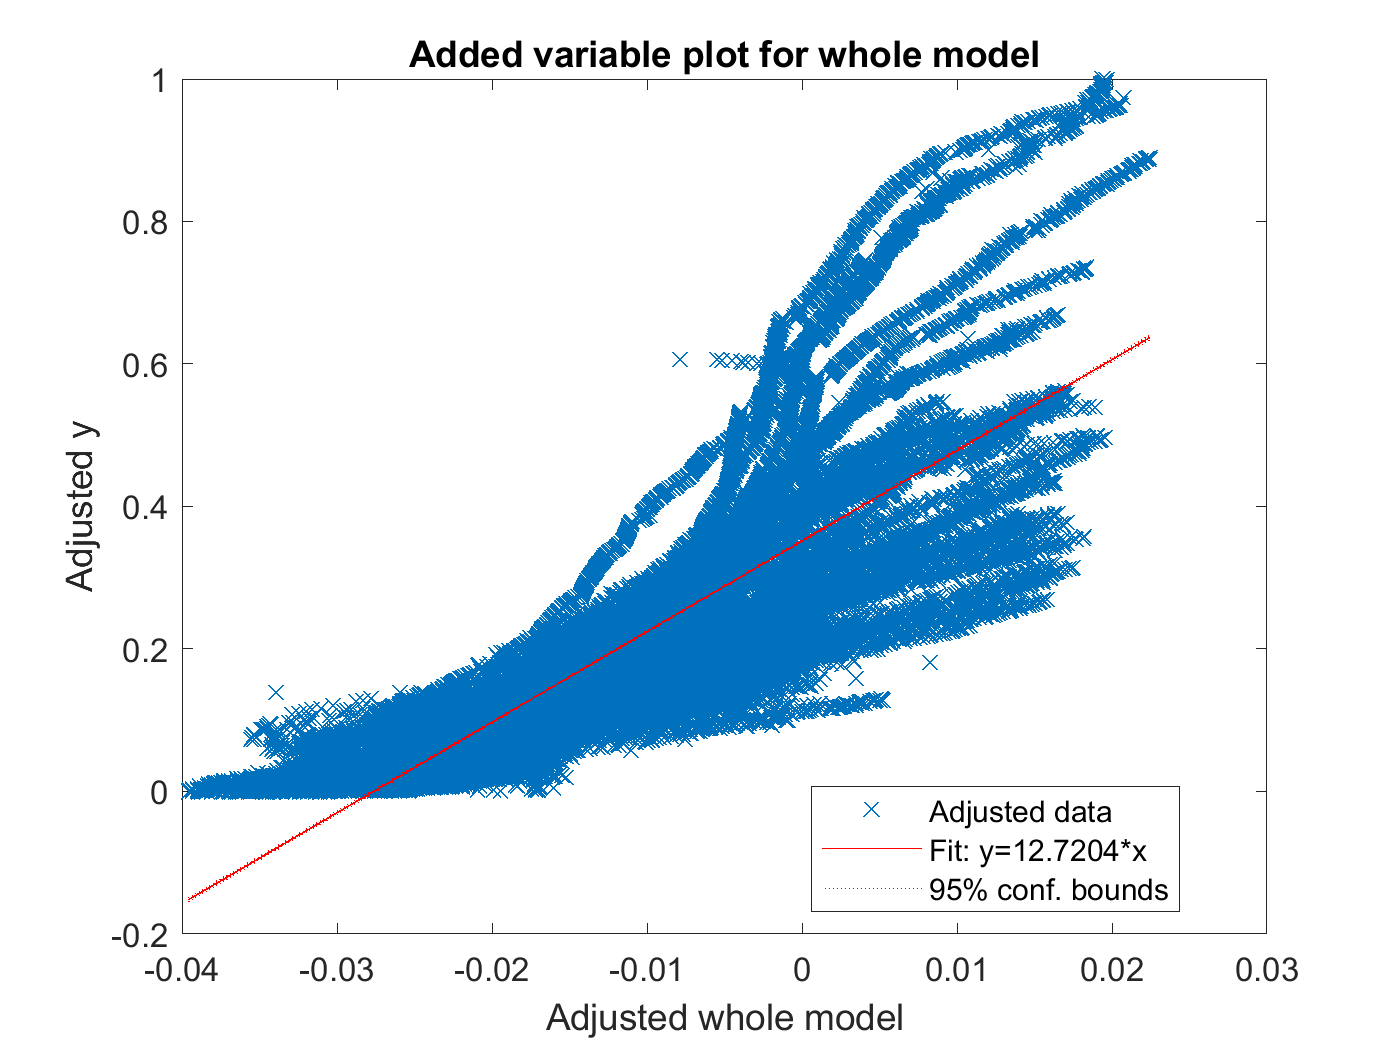


%capHat = Ic(1)

plot(mdl)

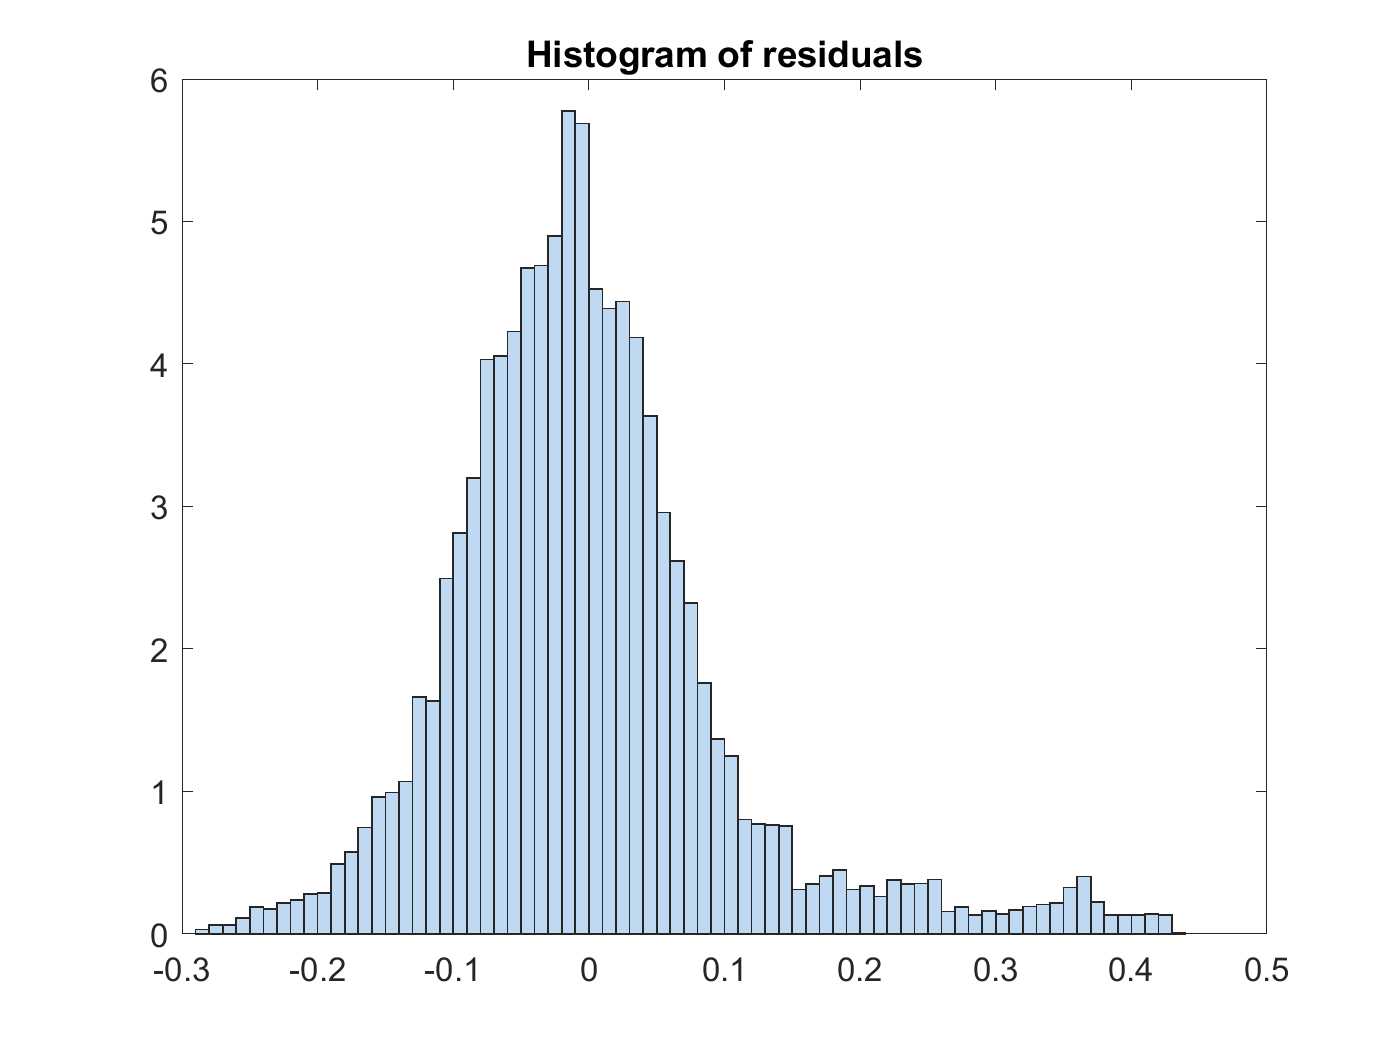

plotResiduals(mdl)




% yfit = predict(mdl,Ic)
yfit = predict(mdl,x_trainValid)

yfit =     0.4490
    0.4577
    0.4475
    0.4580
    0.4433
    0.4403
    0.4403
    0.4385
    0.4368
    0.4355


yfit_test = predict(mdl,x_test)

yfit_test =     0.3780
    0.3759
    0.3743
    0.3705
    0.3698
    0.3690
    0.3657
    0.3647
    0.3633
    0.3602




y= y_trainValid

y =     0.3650
    0.3641
    0.3632
    0.3624
    0.3615
    0.3607
    0.3598
    0.3590
    0.3581
    0.3573


y_test

y_test =     0.2692
    0.2684
    0.2675
    0.2667
    0.2658
    0.2650
    0.2641
    0.2632
    0.2624
    0.2615



% denormalize
yfit = yfit * yrate + ymin;
y = y * yrate + ymin;
yfit_test = yfit_test * yrate + ymin;
y_test = y_test * yrate + ymin;


MAE = mean(abs(yfit-y))

MAE = 87.2495

adjMAE = MAE/range(y)

adjMAE = 0.0746

range(y) % y = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1170


(y - yhat)    % Errors

ans = 	1.0e+03 *

    0.4276
    0.4265
    0.4256
    0.4245
    0.4236
    0.4226
    0.4216
    0.4206
    0.4196
    0.4186


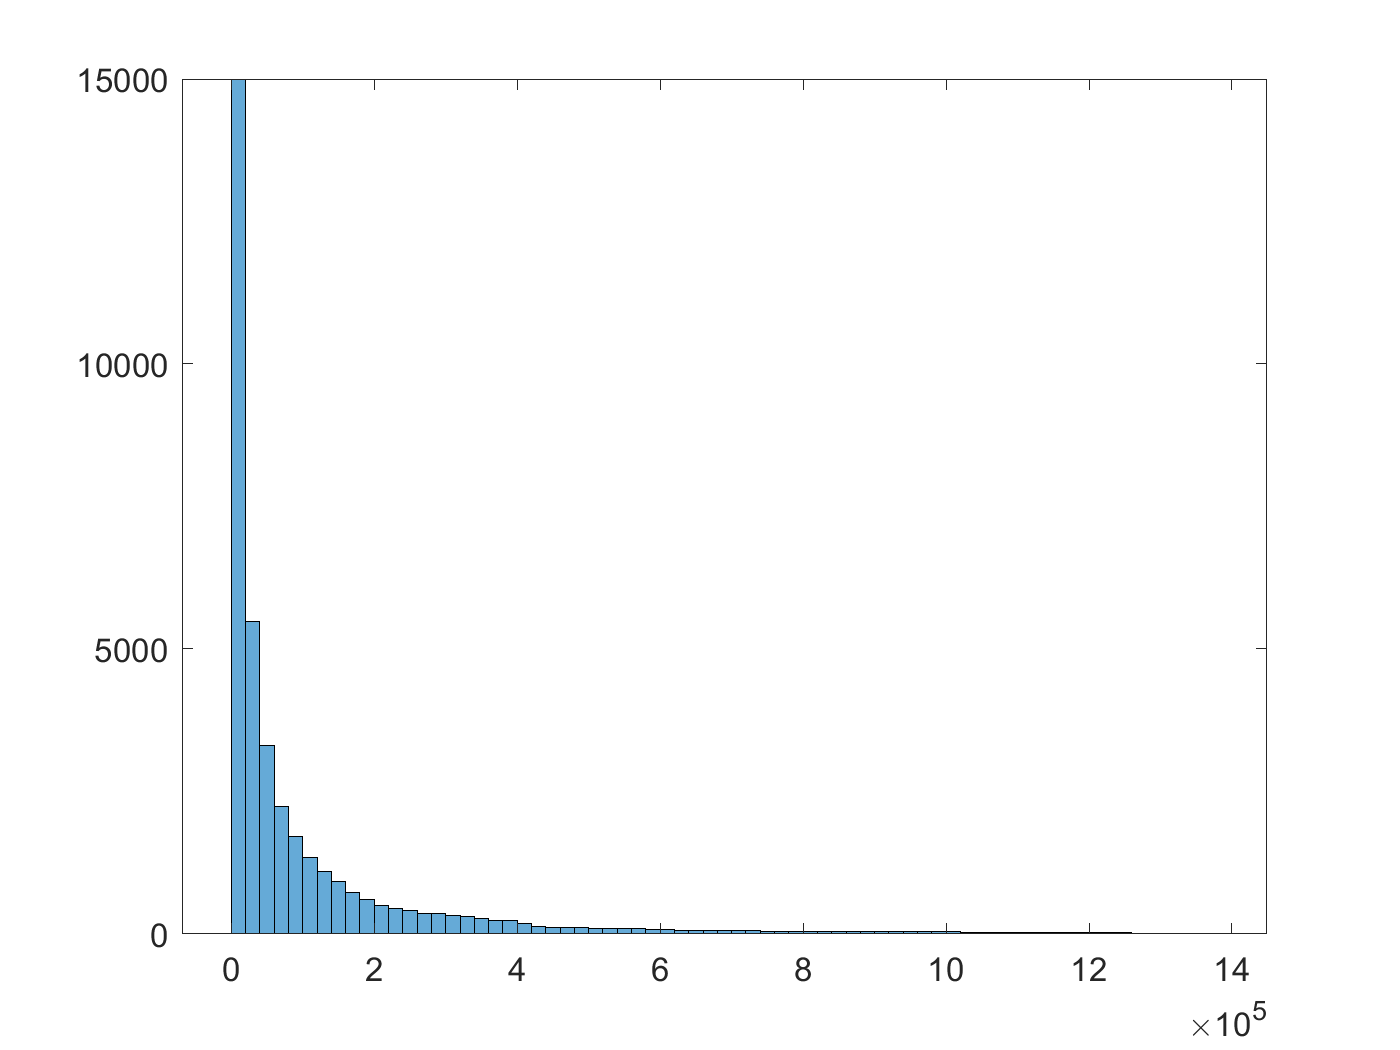

(y - yhat).^2;   % Squared Error
histogram((y - yhat).^2)

mean((y - yhat).^2);   % Mean Squared Error
RMSE = sqrt(mean((y - yhat).^2))  % Root Mean Squared Error

RMSE = 327.7725

(y_test - yfit_test) 

ans =  -127.2287
 -125.7979
 -124.9152
 -121.4400
 -121.6311
 -121.7509
 -118.9089
 -118.7086
 -118.0507
 -115.4700


RMSE_test = sqrt(mean((y_test - yfit_test).^2))

RMSE_test = 125.3460

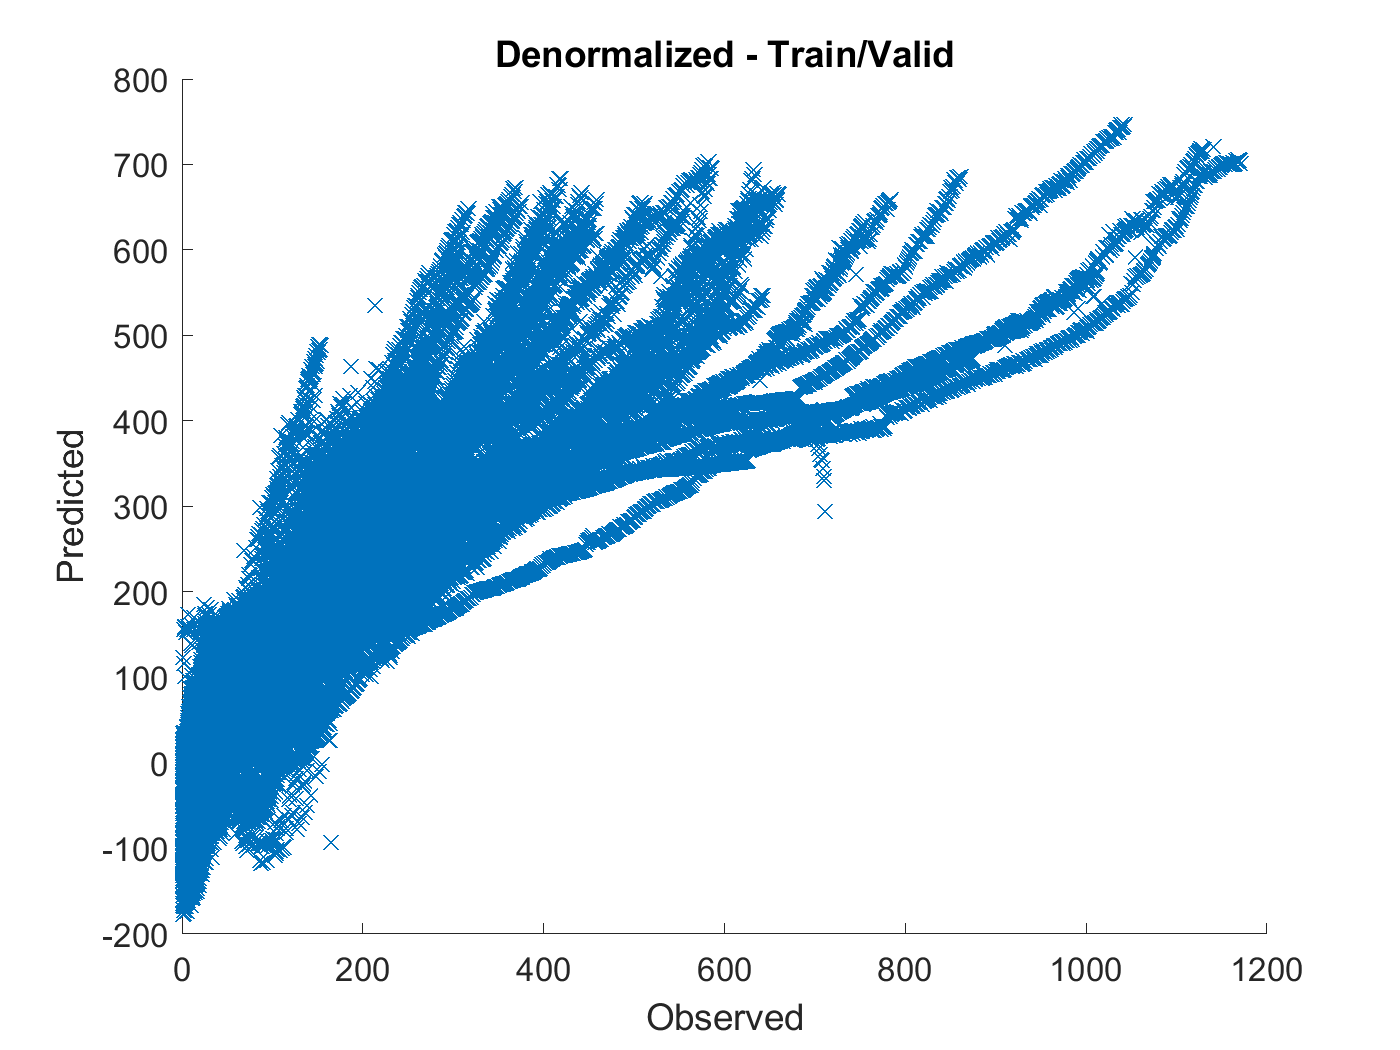


figure
hold on
plot(y,yfit,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Denormalized - Train/Valid'

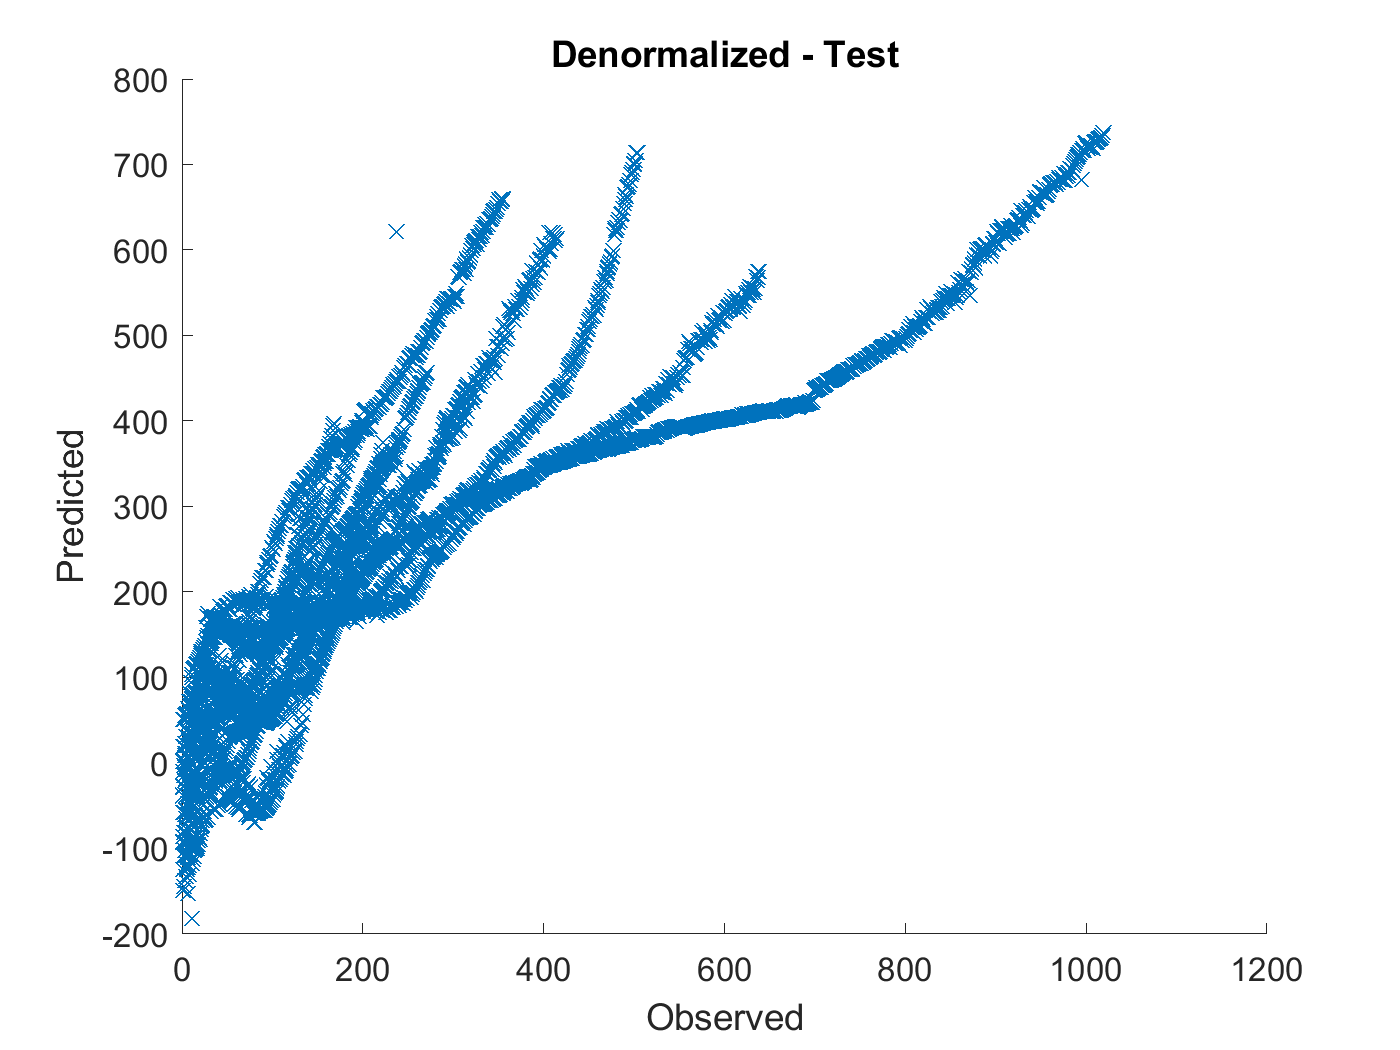


figure
hold on
plot(y_test,yfit_test,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Denormalized - Test'

%xlim([0 1200]), ylim([0 1200])

% 테스트 셋에서는 예측이 전혀 안된다.


# 머신러닝을 위한 기본 설정

epoc_count = 10;
cc_input_size = 20;



- FNN1 - 1 layer


netFNN1_1 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_1.divideFcn = 'divideind';
netFNN1_1.divideParam.trainInd = idxTrainAll;
netFNN1_1.divideParam.valInd = idxValidAll;
netFNN1_1.divideParam.testInd = idxTestAll; 
    
%netFNN1__1.divideParam
% https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
netFNN1_1.trainParam.showWindow = 0; 
netFNN1_1.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
tic
[netFNN1_1, tr] = train(netFNN1_1, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


toc

Elapsed time is 5.223937 seconds.


%tr

# FNN


netFNN1_2 = feedforwardnet(20); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_2.divideFcn = 'divideind';

netFNN1_2.divideFcn = 'divideind';
netFNN1_2.divideParam.trainInd = idxTrainAll;
netFNN1_2.divideParam.valInd = idxValidAll;
netFNN1_2.divideParam.testInd = idxTestAll; 
    
%netFNN1_2.divideParam
netFNN1_2.trainParam.showWindow = 0; 
netFNN1_2.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
tic
netFNN1_2 = train(netFNN1_2, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


toc

Elapsed time is 10.317599 seconds.


netFNN1_3 = feedforwardnet(100); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_3.divideFcn = 'divideind';

netFNN1_3.divideFcn = 'divideind';
netFNN1_3.divideParam.trainInd = idxTrainAll;
netFNN1_3.divideParam.valInd = idxValidAll;
netFNN1_3.divideParam.testInd = idxTestAll; 
    
%netFNN1_3.divideParam
netFNN1_3.trainParam.showWindow = 0; 
netFNN1_3.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
tic
netFNN1_3 = train(netFNN1_3, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


toc

Elapsed time is 187.120572 seconds.



netFNN2_1 = feedforwardnet([20,10]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN2_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN2_1.divideParam.trainInd = tr.trainInd;
netFNN2_1.divideParam.valInd = tr.valInd;
netFNN2_1.divideParam.testInd = tr.testInd; 

netFNN2_1.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN2_1.trainParam.showWindow = 0;
netFNN2_1.trainParam.show = NaN;
tic
[netFNN2_1, tr2] = train(netFNN2_1, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


toc

Elapsed time is 31.527961 seconds.


%view(netFNN2_1)
%netFNN2_1
%tr2

netFNN2_2 = feedforwardnet([50,20]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN2_2.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN2_2.divideParam.trainInd = tr.trainInd;
netFNN2_2.divideParam.valInd = tr.valInd;
netFNN2_2.divideParam.testInd = tr.testInd; 

netFNN2_2.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN2_2.trainParam.show = NaN;
netFNN2_2.trainParam.showWindow = 0;
tic
netFNN2_2 = train(netFNN2_1, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


toc

Elapsed time is 13.268886 seconds.


%view(netFNN2_1)
%netFNN2_1
%tr2

netFNN3_1 = feedforwardnet([50,20,10]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN3_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN3_1.divideParam.trainInd = tr.trainInd;
netFNN3_1.divideParam.valInd = tr.valInd;
netFNN3_1.divideParam.testInd = tr.testInd; 

netFNN3_1.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN3_1.trainParam.show = NaN;
netFNN3_1.trainParam.showWindow = 0;
tic
netFNN3_1 = train(netFNN3_1, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


toc

Elapsed time is 227.663798 seconds.


%view(netFNN3_1)

netFNN4_1 = feedforwardnet([50,20,10,5]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN4_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN4_1.divideParam.trainInd = tr.trainInd;
netFNN4_1.divideParam.valInd = tr.valInd;
netFNN4_1.divideParam.testInd = tr.testInd; 

netFNN4_1.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN4_1.trainParam.show = NaN;
netFNN4_1.trainParam.showWindow = 0;
tic
netFNN4_1 = train(netFNN4_1, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


toc

Elapsed time is 258.547057 seconds.


%view(netFNN3_1)

netFNN5_1 = feedforwardnet([50,20,10,5,5]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN5_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN5_1.divideParam.trainInd = tr.trainInd;
netFNN5_1.divideParam.valInd = tr.valInd;
netFNN5_1.divideParam.testInd = tr.testInd; 

netFNN5_1.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN5_1.trainParam.show = NaN;
netFNN5_1.trainParam.showWindow = 0;
tic
netFNN5_1 = train(netFNN5_1, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


toc

Elapsed time is 218.118551 seconds.


%view(netFNN3_1)

pFNN1_1 = netFNN1_1(xnorm(tr.testInd, :)');
pFNN1_2 = netFNN1_2(xnorm(tr.testInd, :)');
pFNN1_3 = netFNN1_3(xnorm(tr.testInd, :)');
pFNN2_1 = netFNN2_1(xnorm(tr.testInd, :)');
pFNN2_2 = netFNN2_2(xnorm(tr.testInd, :)');
pFNN3_1 = netFNN3_1(xnorm(tr.testInd, :)');
pFNN4_1 = netFNN4_1(xnorm(tr.testInd, :)');
pFNN5_1 = netFNN5_1(xnorm(tr.testInd, :)');

ytest = ynorm(tr.testInd, :)*yrate + ymin;
pFNN1_1_hat = pFNN1_1 * yrate + ymin;
pFNN1_2_hat = pFNN1_2 * yrate + ymin;
pFNN1_3_hat = pFNN1_3 * yrate + ymin;
pFNN2_1_hat = pFNN2_1 * yrate + ymin;
pFNN2_2_hat = pFNN2_2 * yrate + ymin;
pFNN3_1_hat = pFNN3_1 * yrate + ymin;
pFNN4_1_hat = pFNN4_1 * yrate + ymin;
pFNN5_1_hat = pFNN5_1 * yrate + ymin;


rmse_pFNN1_1_hat = sqrt(mean(( ytest' - pFNN1_1_hat ).^2))

rmse_pFNN1_1_hat = 94.0085

rmse_pFNN1_2_hat = sqrt(mean(( ytest' - pFNN1_2_hat ).^2))

rmse_pFNN1_2_hat = 92.0184

rmse_pFNN1_3_hat = sqrt(mean(( ytest' - pFNN1_3_hat ).^2))

rmse_pFNN1_3_hat = 113.6041

rmse_pFNN2_1_hat = sqrt(mean(( ytest' - pFNN2_1_hat ).^2))

rmse_pFNN2_1_hat = 100.0282

rmse_pFNN2_2_hat = sqrt(mean(( ytest' - pFNN2_2_hat ).^2))

rmse_pFNN2_2_hat = 100.0282

rmse_pFNN3_1_hat = sqrt(mean(( ytest' - pFNN3_1_hat ).^2))

rmse_pFNN3_1_hat = 90.8179

rmse_pFNN4_1_hat = sqrt(mean(( ytest' - pFNN4_1_hat ).^2))

rmse_pFNN4_1_hat = 102.8041

rmse_pFNN5_1_hat = sqrt(mean(( ytest' - pFNN5_1_hat ).^2))

rmse_pFNN5_1_hat = 84.6365

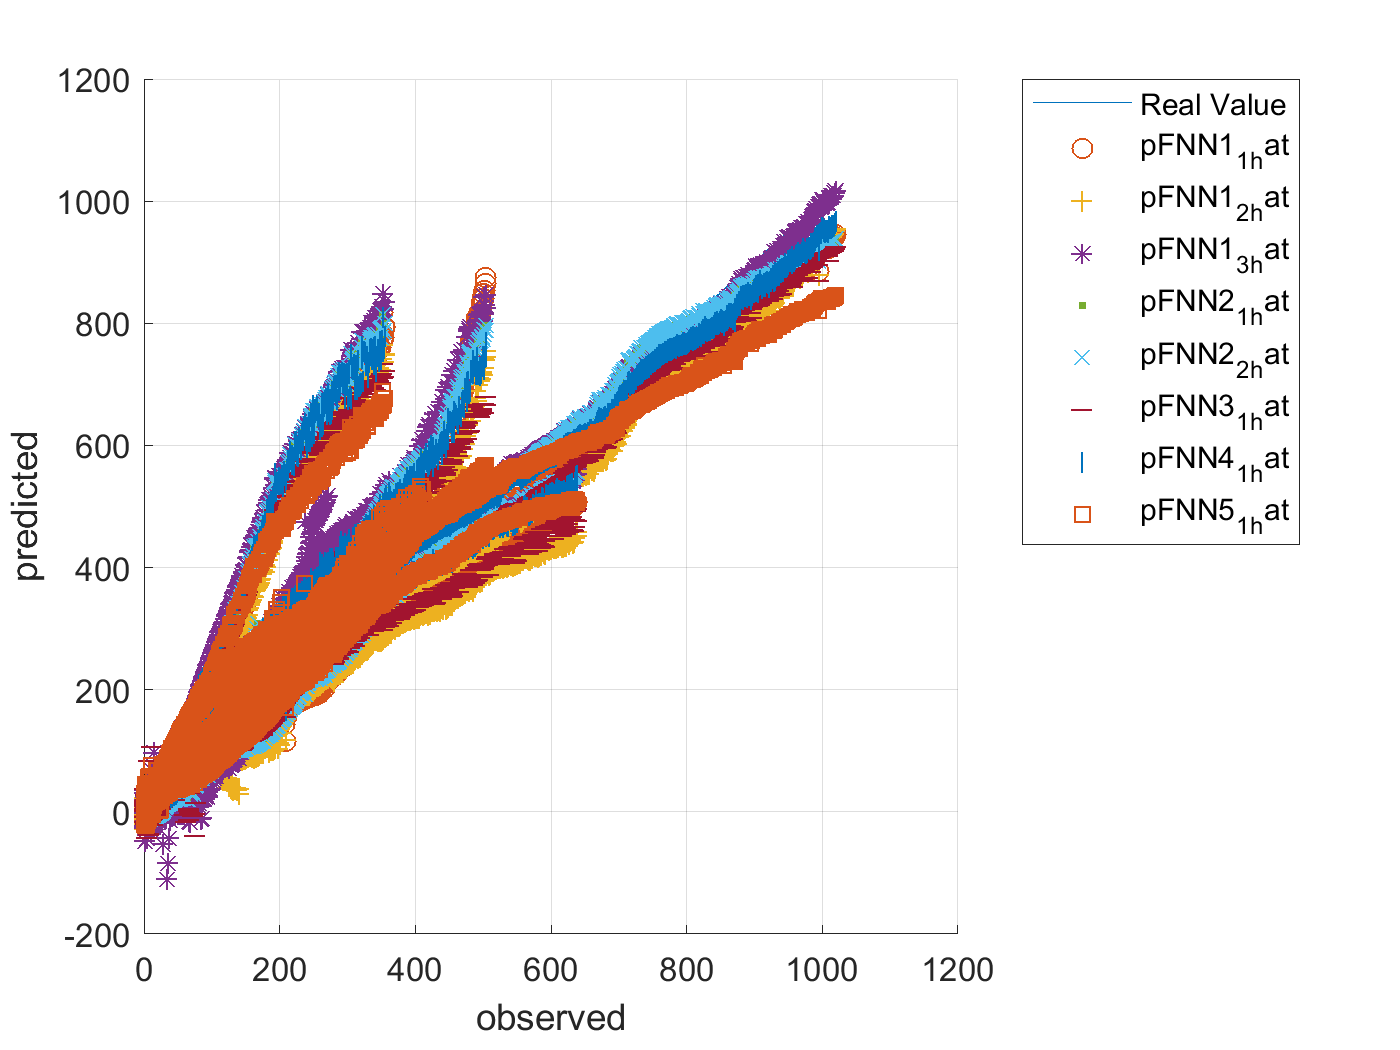


figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pFNN1_1_hat,'o')
plot(ytest,pFNN1_2_hat,'+')
plot(ytest,pFNN1_3_hat,'*')
plot(ytest,pFNN2_1_hat,'.')
plot(ytest,pFNN2_2_hat,'x')
plot(ytest,pFNN3_1_hat,'_')
plot(ytest,pFNN4_1_hat,'|')
plot(ytest,pFNN5_1_hat,'s')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pFNN1_1_hat', ... 
		'pFNN1_2_hat', ...
		'pFNN1_3_hat', ... 	
		'pFNN2_1_hat', ... 
		'pFNN2_2_hat', ... 
		'pFNN3_1_hat', ... 
		'pFNN4_1_hat', ... 
		'pFNN5_1_hat','Location','northeastoutside')

ryan3_model_chargeCurrent_RUL1_desc = 'ryan3_model_chargeCurrent_RUL1';
save('ryan3_model_chargeCurrent_RUL1.mat','ryan3_model_chargeCurrent_RUL1_desc')
save('ryan3_model_chargeCurrent_RUL1.mat','netFNN1_1' ,'-append')
save('ryan3_model_chargeCurrent_RUL1.mat','netFNN1_2' ,'-append')
save('ryan3_model_chargeCurrent_RUL1.mat','netFNN1_3' ,'-append')
save('ryan3_model_chargeCurrent_RUL1.mat','netFNN2_1' ,'-append')
save('ryan3_model_chargeCurrent_RUL1.mat','netFNN2_2' ,'-append')
save('ryan3_model_chargeCurrent_RUL1.mat','netFNN3_1' ,'-append')
save('ryan3_model_chargeCurrent_RUL1.mat','netFNN4_1' ,'-append')
save('ryan3_model_chargeCurrent_RUL1.mat','netFNN5_1' ,'-append')

pFNN1_1_self = netFNN1_1(xnorm([tr.trainInd tr.valInd], :)');
pFNN1_2_self = netFNN1_2(xnorm([tr.trainInd tr.valInd], :)');
pFNN1_3_self = netFNN1_3(xnorm([tr.trainInd tr.valInd], :)');
pFNN2_1_self = netFNN2_1(xnorm([tr.trainInd tr.valInd], :)');
pFNN2_2_self = netFNN2_2(xnorm([tr.trainInd tr.valInd], :)');
pFNN3_1_self = netFNN3_1(xnorm([tr.trainInd tr.valInd], :)');
pFNN4_1_self = netFNN4_1(xnorm([tr.trainInd tr.valInd], :)');
pFNN5_1_self = netFNN5_1(xnorm([tr.trainInd tr.valInd], :)');

ytrain_self = ynorm([tr.trainInd tr.valInd], :)*yrate + ymin;
pFNN1_1_self_hat = pFNN1_1_self * yrate + ymin;
pFNN1_2_self_hat = pFNN1_2_self * yrate + ymin;
pFNN1_3_self_hat = pFNN1_3_self * yrate + ymin;
pFNN2_1_self_hat = pFNN2_1_self * yrate + ymin;
pFNN2_2_self_hat = pFNN2_2_self * yrate + ymin;
pFNN3_1_self_hat = pFNN3_1_self * yrate + ymin;
pFNN4_1_self_hat = pFNN4_1_self * yrate + ymin;
pFNN5_1_self_hat = pFNN5_1_self * yrate + ymin;


rmse_pFNN1_1_self_hat = sqrt(mean(( ytrain_self' - pFNN1_1_self_hat ).^2))

rmse_pFNN1_1_self_hat = 94.3825

rmse_pFNN1_2_self_hat = sqrt(mean(( ytrain_self' - pFNN1_2_self_hat ).^2))

rmse_pFNN1_2_self_hat = 93.8778

rmse_pFNN1_3_self_hat = sqrt(mean(( ytrain_self' - pFNN1_3_self_hat ).^2))

rmse_pFNN1_3_self_hat = 101.6384

rmse_pFNN2_1_self_hat = sqrt(mean(( ytrain_self' - pFNN2_1_self_hat ).^2))

rmse_pFNN2_1_self_hat = 99.4027

rmse_pFNN2_2_self_hat = sqrt(mean(( ytrain_self' - pFNN2_2_self_hat ).^2))

rmse_pFNN2_2_self_hat = 99.4027

rmse_pFNN3_1_self_hat = sqrt(mean(( ytrain_self' - pFNN3_1_self_hat ).^2))

rmse_pFNN3_1_self_hat = 95.1569

rmse_pFNN4_1_self_hat = sqrt(mean(( ytrain_self' - pFNN4_1_self_hat ).^2))

rmse_pFNN4_1_self_hat = 94.7290

rmse_pFNN5_1_self_hat = sqrt(mean(( ytrain_self' - pFNN5_1_self_hat ).^2))

rmse_pFNN5_1_self_hat = 98.2018

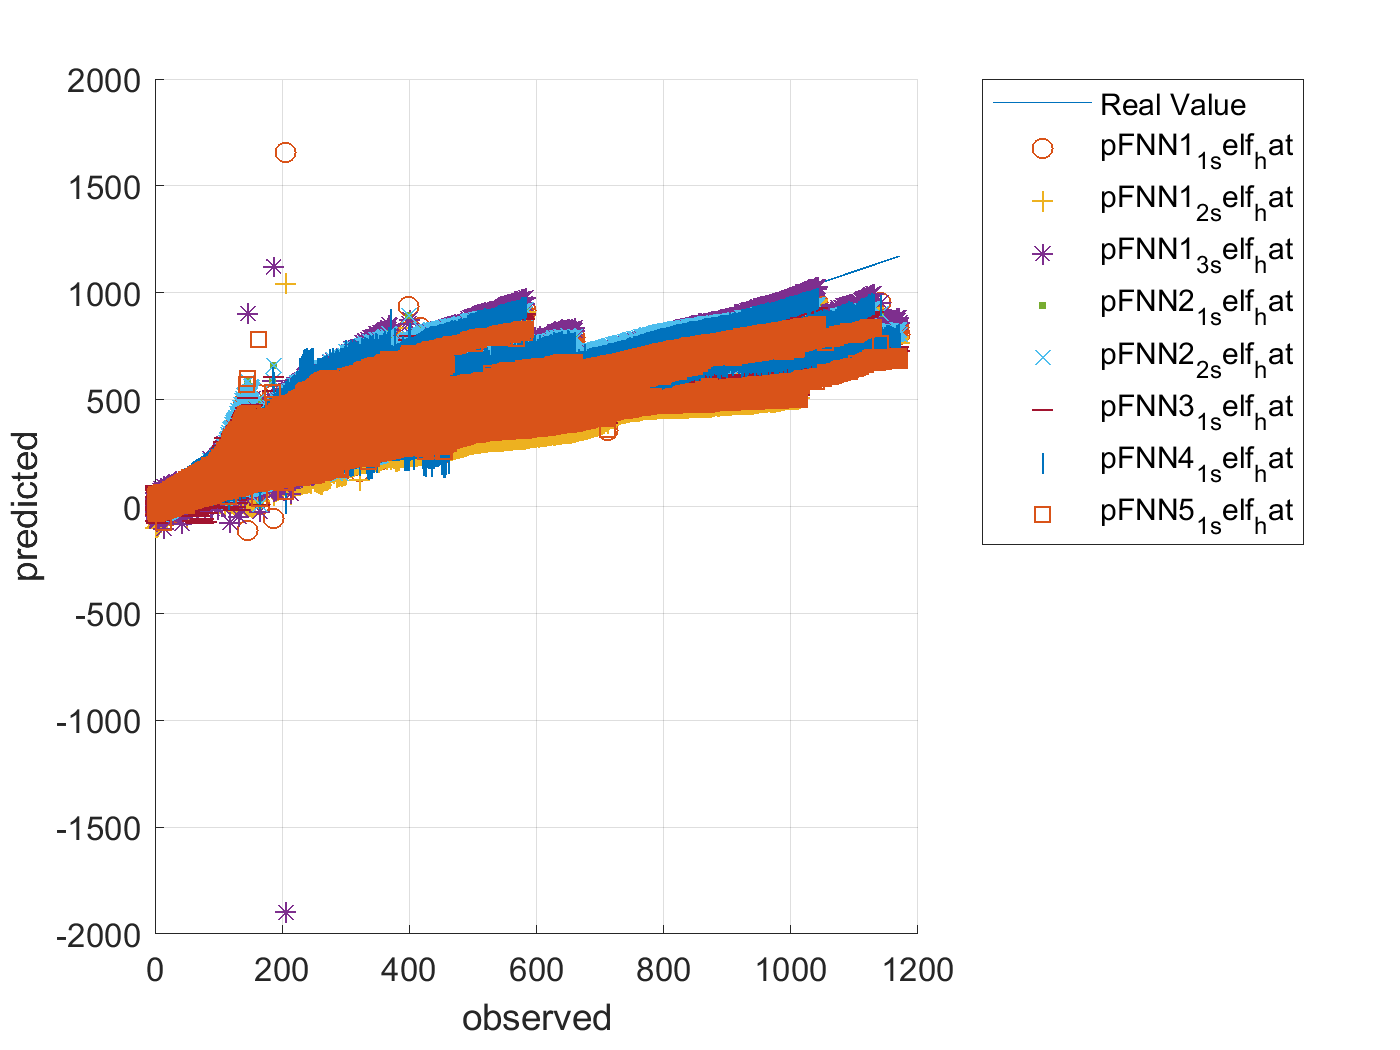



figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pFNN1_1_self_hat,'o')
plot(ytrain_self,pFNN1_2_self_hat,'+')
plot(ytrain_self,pFNN1_3_self_hat,'*')
plot(ytrain_self,pFNN2_1_self_hat,'.')
plot(ytrain_self,pFNN2_2_self_hat,'x')
plot(ytrain_self,pFNN3_1_self_hat,'_')
plot(ytrain_self,pFNN4_1_self_hat,'|')
plot(ytrain_self,pFNN5_1_self_hat,'s')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pFNN1_1_self_hat', ... 
		'pFNN1_2_self_hat', ...
		'pFNN1_3_self_hat', ... 	
		'pFNN2_1_self_hat', ... 
		'pFNN2_2_self_hat', ... 
		'pFNN3_1_self_hat', ... 
		'pFNN4_1_self_hat', ... 
		'pFNN5_1_self_hat','Location','northeastoutside')

# CNN

% For CNN
filterSize = 3;
numFilters = 32;
numFCN = 1;


- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:16 |         0.27 |         0.23 |       0.0358 |       0.0260 |          0.0010 |
|       1 |          50 |       00:00:20 |         0.18 |         0.17 |       0.0159 |       0.0143 |          0.0010 |
|       1 |         100 |       00:00:23 |         0.19 |         0.15 |       0.0173 |       0.0118 |          0.0010 |
|       1 |         150 |       00:00:27 |         0.16 |         0.14 |       0.0125 |   

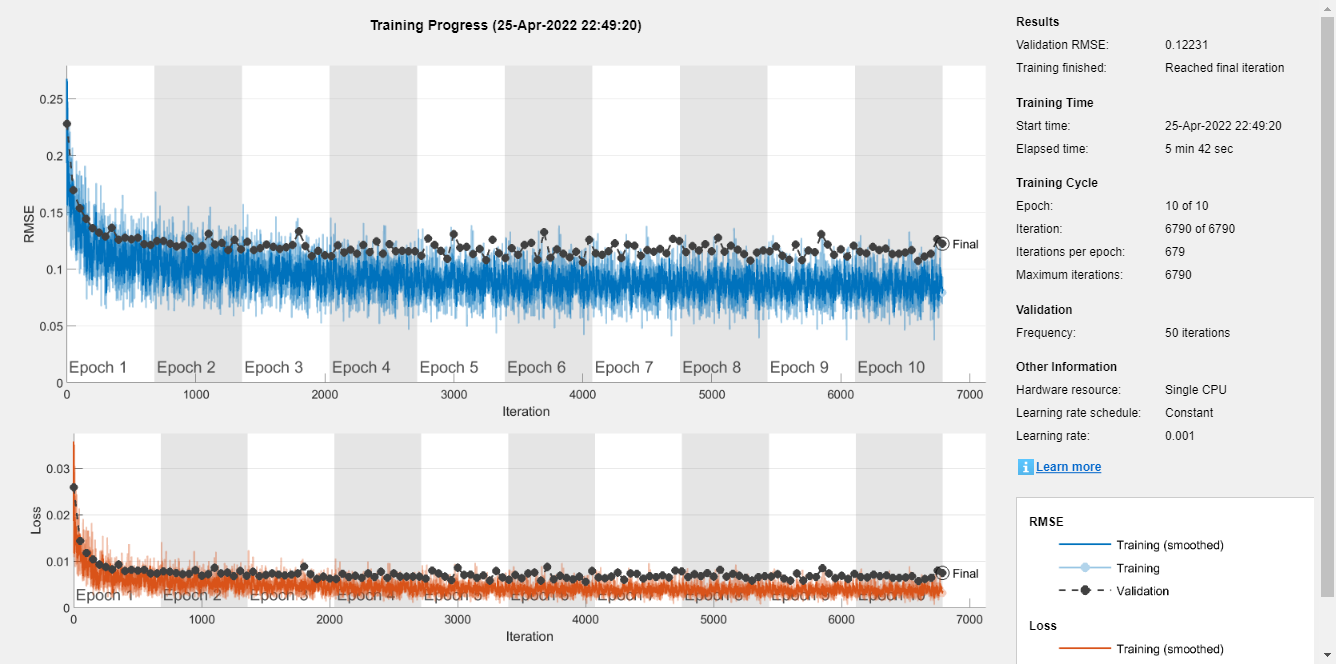



layerCNN2_1 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];
cellx = num2cell(xnorm', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(ynorm);
tbl = table(cellx);
tbl.cellyB = cellyB;


Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
 'InitialLearnRate', 0.001, ...
 'MaxEpochs',epoc_count, ...
 'MiniBatchSize',50, ...
 'Plots','training-progress', 'ValidationData', valtbl);

tic
netCNN2_1 = trainNetwork(Traintbl, layerCNN2_1, options);

toc

Elapsed time is 397.563169 seconds.


- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:09 |         0.25 |         0.29 |       0.0321 |       0.0410 |          0.0010 |
|       1 |          50 |       00:00:12 |         0.18 |         0.17 |       0.0163 |       0.0151 |          0.0010 |
|       1 |         100 |       00:00:15 |         0.11 |         0.16 |       0.0064 |       0.0124 |          0.0010 |
|       1 |         150 |       00:00:17 |         0.12 |         0.15 |       0.0076 |   

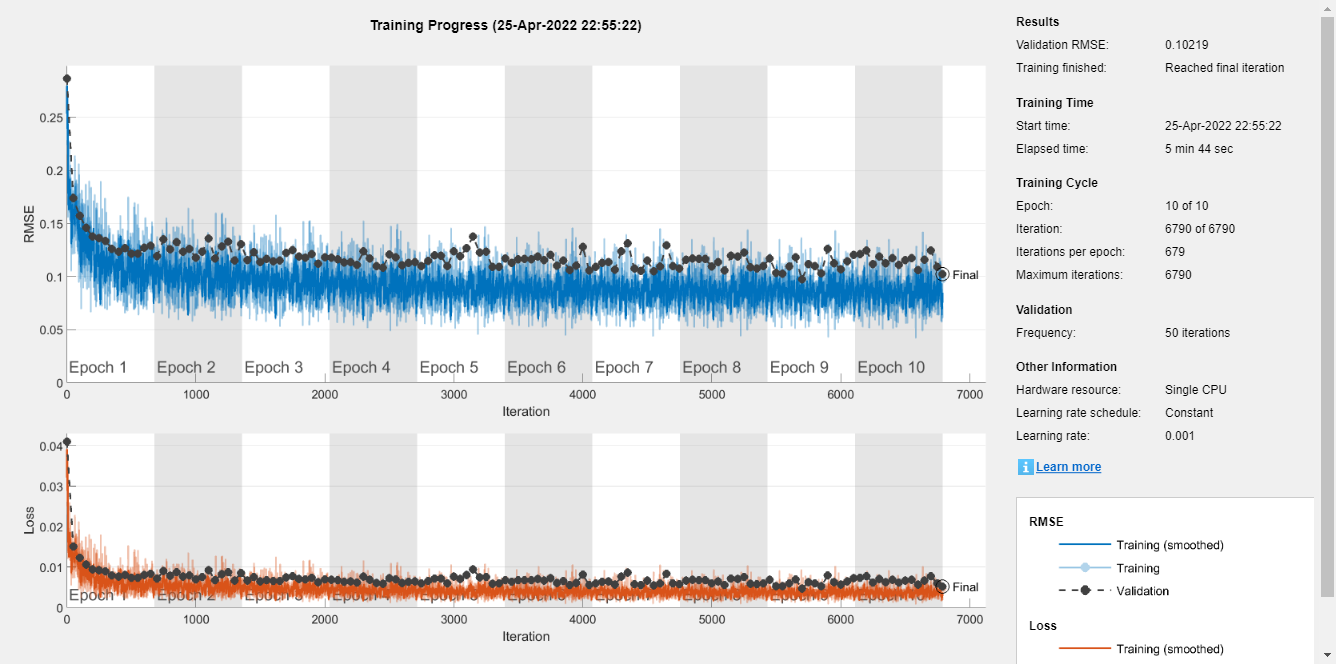

layerCNN2_2 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];

tic
netCNN2_2 = trainNetwork(Traintbl, layerCNN2_1, options);

toc

Elapsed time is 362.052685 seconds.


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |         0.23 |         0.29 |       0.0262 |       0.0412 |          0.0010 |
|       1 |          50 |       00:00:09 |         0.19 |         0.18 |       0.0174 |       0.0158 |          0.0010 |
|       1 |         100 |       00:00:11 |         0.11 |         0.17 |       0.0056 |       0.0140 |          0.0010 |
|       1 |         150 |       00:00:13 |         0.12 |         0.16 |       0.0067 |   

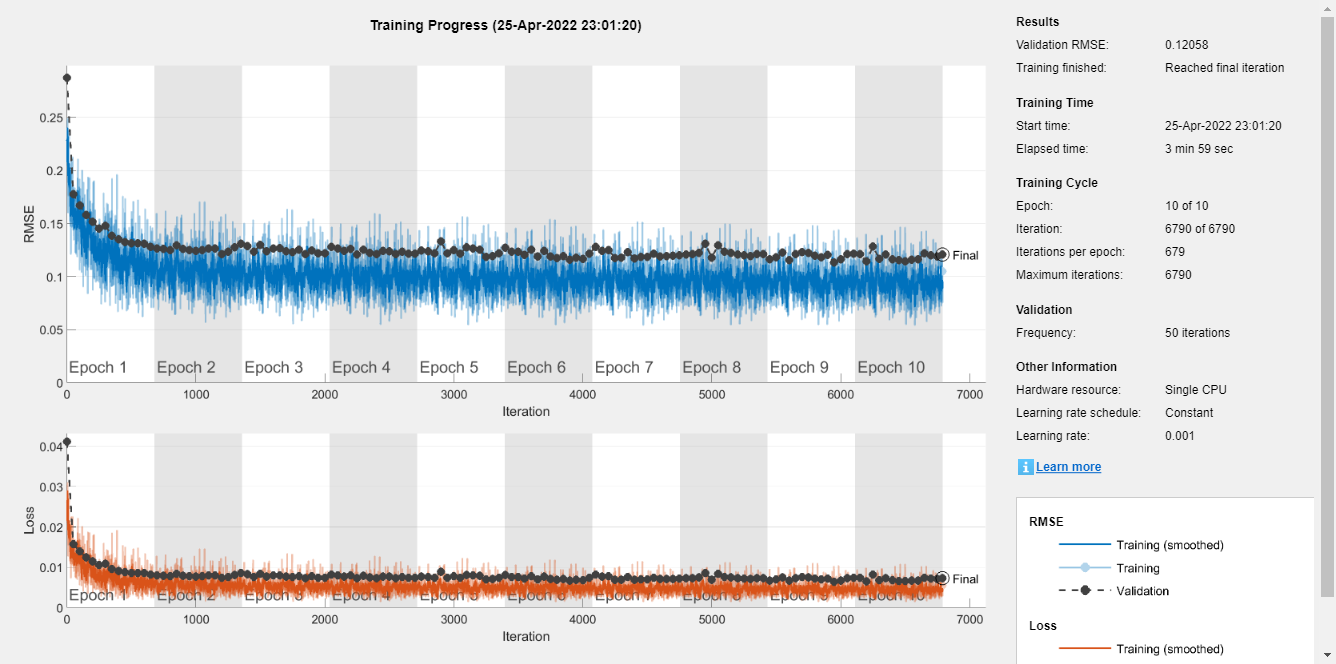





layerCNN1_1 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];
%     sequenceInputLayer(input_size)
%     convolution1dLayer(filterSize,numFilters)
%     reluLayer
%     globalMaxPooling1dLayer
%     fullyConnectedLayer(numFCN)
%     %softmaxLayer
%     regressionLayer();]
tic
netCNN1_1 = trainNetwork(Traintbl, layerCNN1_1, options);

toc

Elapsed time is 253.530356 seconds.


%%%% 시간이 오래 걸린다. 
%{
layerCNN2_3 = [ ...
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    globalAveragePooling2dLayer
    fullyConnectedLayer(numFCN)
    %softmaxLayer
    regressionLayer();];
tic
netCNN2_3 = trainNetwork(Traintbl, layerCNN2_3, options);
toc

layerCNN2_4 = [ ...
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
     reluLayer
    layerNormalizationLayer
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    globalAveragePooling2dLayer
    fullyConnectedLayer(numFCN)
    %softmaxLayer
    regressionLayer();];
tic
netCNN2_4 = trainNetwork(Traintbl, layerCNN2_4, options);
toc


figure
plot(xnorm')
xlabel("Qc")
title("Training Observation 1")
numFeatures = size(xnorm,1);
legend("Feature " + string(1:numFeatures),Location="northeastoutside")
%}
%%%%%%%%%%%%%%


cellx = num2cell(xnorm(tr.testInd, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);

x_4d = zeros(1, cc_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN2_1 = predict(netCNN2_1, x_4d);
pCNN2_2 = predict(netCNN2_2, x_4d);
%pCNN2_3 = predict(netCNN2_3, x_4d);
%pCNN2_4 = predict(netCNN2_4, x_4d);
pCNN1_1 = predict(netCNN1_1, x_4d);



ytest = ynorm(tr.testInd, :)*yrate + ymin;
pCNN2_1_hat = pCNN2_1 * yrate + ymin;
pCNN2_2_hat = pCNN2_2 * yrate + ymin;
%pCNN2_3_hat = pCNN2_3 * yrate + ymin;
%pCNN2_4_hat = pCNN2_4 * yrate + ymin;
pCNN1_1_hat = pCNN1_1 * yrate + ymin;


rmse_pCNN2_1_hat = sqrt(mean(( ytest' - pCNN2_1_hat' ).^2))

rmse_pCNN2_1_hat = single
105.3867

rmse_pCNN2_2_hat = sqrt(mean(( ytest' - pCNN2_2_hat' ).^2))

rmse_pCNN2_2_hat = single
113.3795

%rmse_pCNN2_3_hat = sqrt(mean(( ytest' - pCNN2_3_hat' ).^2))
%rmse_pCNN2_4_hat = sqrt(mean(( ytest' - pCNN2_4_hat' ).^2))
rmse_pCNN1_1_hat = sqrt(mean(( ytest' - pCNN1_1_hat' ).^2))

rmse_pCNN1_1_hat = single
112.9806

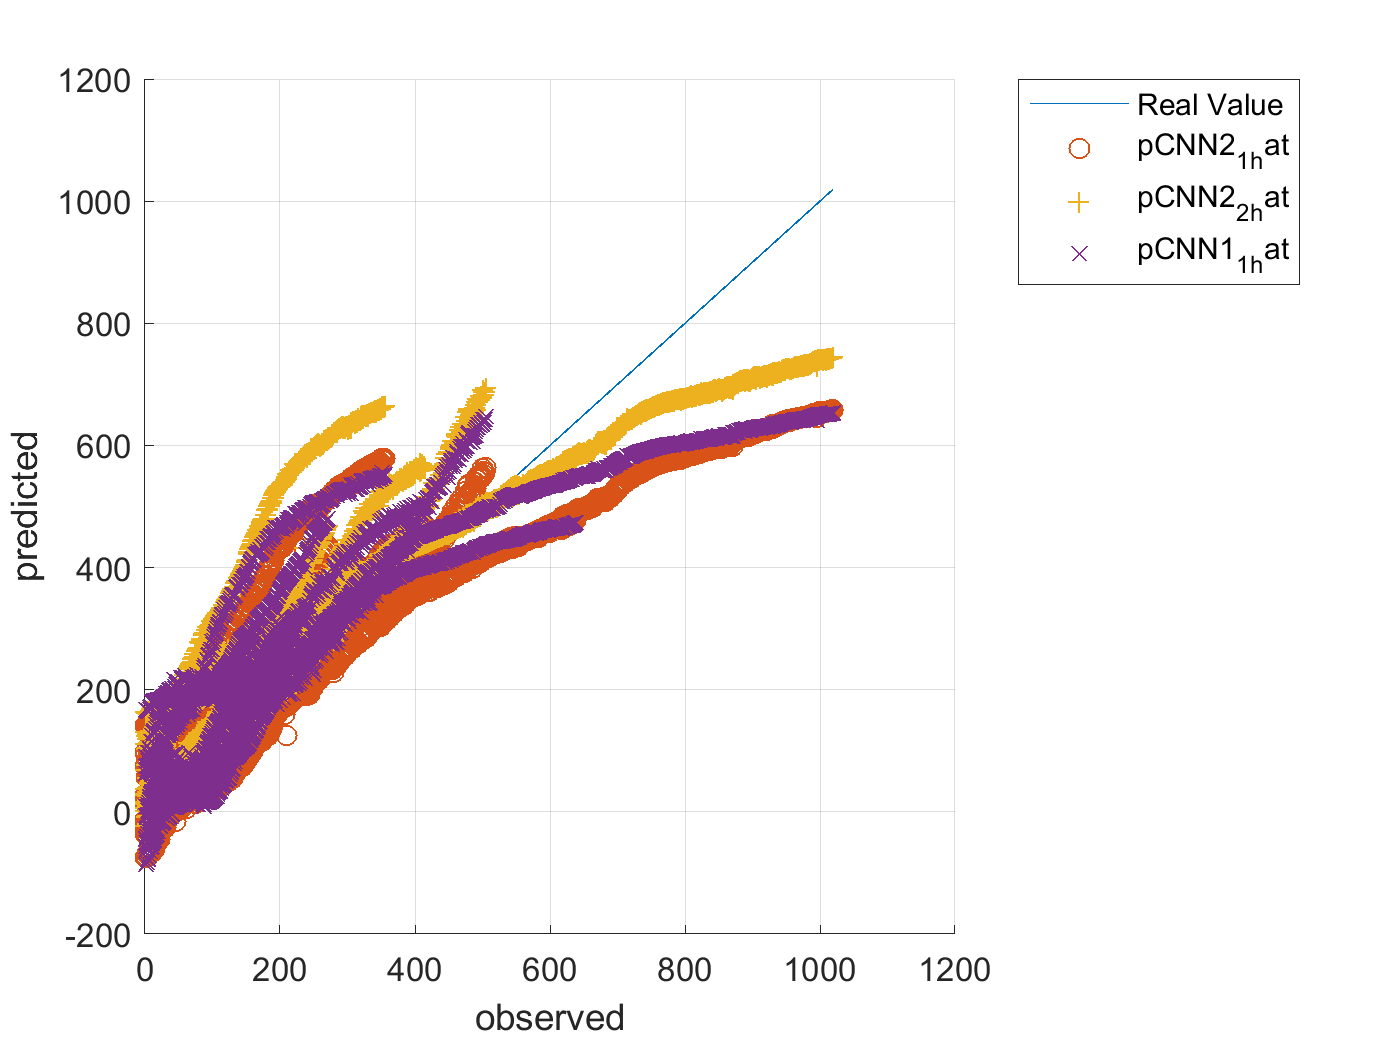




figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pCNN2_1_hat,'o')
plot(ytest,pCNN2_2_hat,'+')
%plot(ytest,pCNN2_3_hat,'*')
%plot(ytest,pCNN2_4_hat,'.')
plot(ytest,pCNN1_1_hat,'x')

hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pCNN2_1_hat', ... 
		'pCNN2_2_hat', ...
		'pCNN1_1_hat','Location','northeastoutside')




save('ryan3_model_chargeCurrent_RUL1.mat','netCNN2_1' ,'-append')
save('ryan3_model_chargeCurrent_RUL1.mat','netCNN2_2' ,'-append')
%save('ryan3_model_chargeCurrent_RUL1.mat','netCNN2_3' ,'-append')
%save('ryan3_model_chargeCurrent_RUL1.mat','netCNN2_4' ,'-append')
save('ryan3_model_chargeCurrent_RUL1.mat','netCNN1_1' ,'-append')

cellx_self = num2cell(xnorm([tr.trainInd tr.valInd], :)', 1)';
cellx_self = cellfun(@transpose, cellx_self, 'UniformOutput', false);
tbl_self = table(cellx_self);

x_4d_self = zeros(1, cc_input_size, 1, height(tbl_self));
for i = 1:height(tbl_self)
    x_4d_self(:,:,:,i) = tbl_self.cellx_self{i};
end

pCNN2_1_self = predict(netCNN2_1, x_4d_self);
pCNN2_2_self = predict(netCNN2_2, x_4d_self);
%pCNN2_3_self = predict(netCNN2_3, x_4d_self);
%pCNN2_4_self = predict(netCNN2_4, x_4d_self);
pCNN1_1_self = predict(netCNN1_1, x_4d_self);

ytrain_self = ynorm([tr.trainInd tr.valInd], :)*yrate + ymin;
pCNN2_1_self_hat = pCNN2_1_self * yrate + ymin;
pCNN2_2_self_hat = pCNN2_2_self * yrate + ymin;
%pCNN2_3_self_hat = pCNN2_3_self * yrate + ymin;
%pCNN2_4_self_hat = pCNN2_4_self * yrate + ymin;
pCNN1_1_self_hat = pCNN1_1_self * yrate + ymin;



rmse_pCNN2_1_self_hat = sqrt(mean(( ytrain_self' - pCNN2_1_self_hat' ).^2))

rmse_pCNN2_1_self_hat = single
108.4750

rmse_pCNN2_2_self_hat = sqrt(mean(( ytrain_self' - pCNN2_2_self_hat' ).^2))

rmse_pCNN2_2_self_hat = single
107.2797

%rmse_pCNN2_3_self_hat = sqrt(mean(( ytrain_self' - pCNN2_3_self_hat' ).^2))
%rmse_pCNN2_4_self_hat = sqrt(mean(( ytrain_self' - pCNN2_4_self_hat' ).^2))
rmse_pCNN1_1_self_hat = sqrt(mean(( ytrain_self' - pCNN1_1_self_hat' ).^2))

rmse_pCNN1_1_self_hat = single
113.9942

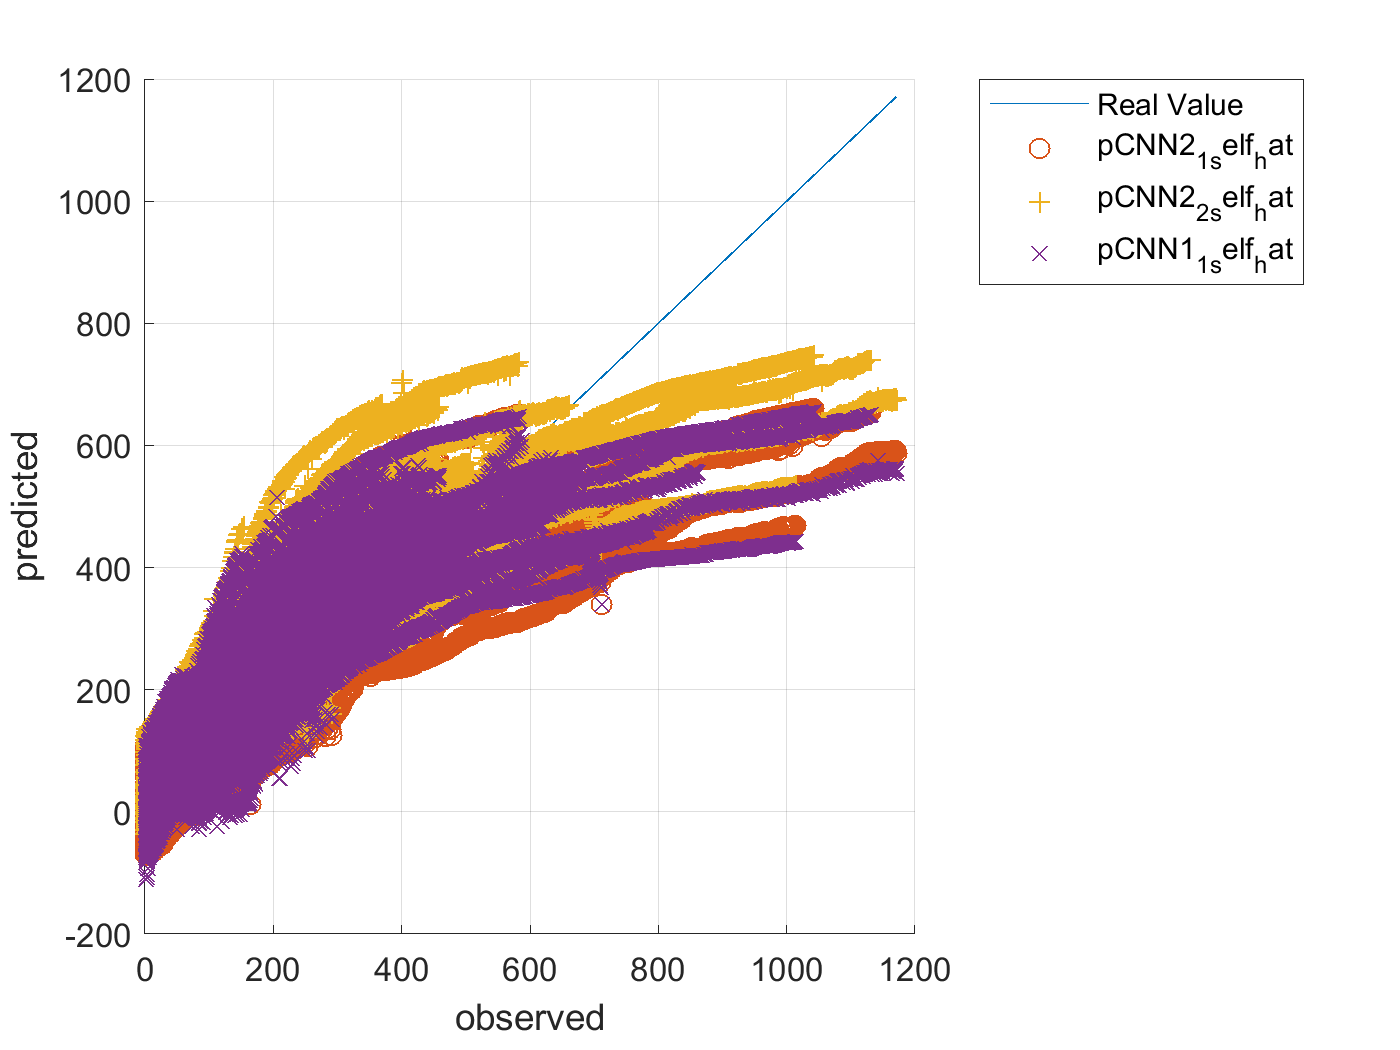




figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pCNN2_1_self_hat,'o')
plot(ytrain_self,pCNN2_2_self_hat,'+')
%plot(ytrain_self,pCNN2_3_self_hat,'*')
%plot(ytrain_self,pCNN2_4_self_hat,'.')
plot(ytrain_self,pCNN1_1_self_hat,'x')

hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pCNN2_1_self_hat', ... 
		'pCNN2_2_self_hat', ...
		'pCNN1_1_self_hat','Location','northeastoutside')

# LSTM

- LSTM : 1 lstm layer with 5 hidden units

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:12 |         0.14 |         0.19 |       0.0095 |       0.0195 |          0.0010 |
|       1 |          50 |       00:00:17 |         0.14 |         0.17 |       0.0095 |       0.0143 |          0.0010 |
|       1 |         100 |       00:00:23 |         0.13 |         0.16 |       0.0088 |       0.0129 |          0.0010 |
|       1 |         150 |       00:00:28 |         0.14 |         0.15 |       0.0103 |       0.0113 |          0.0010 |
|       

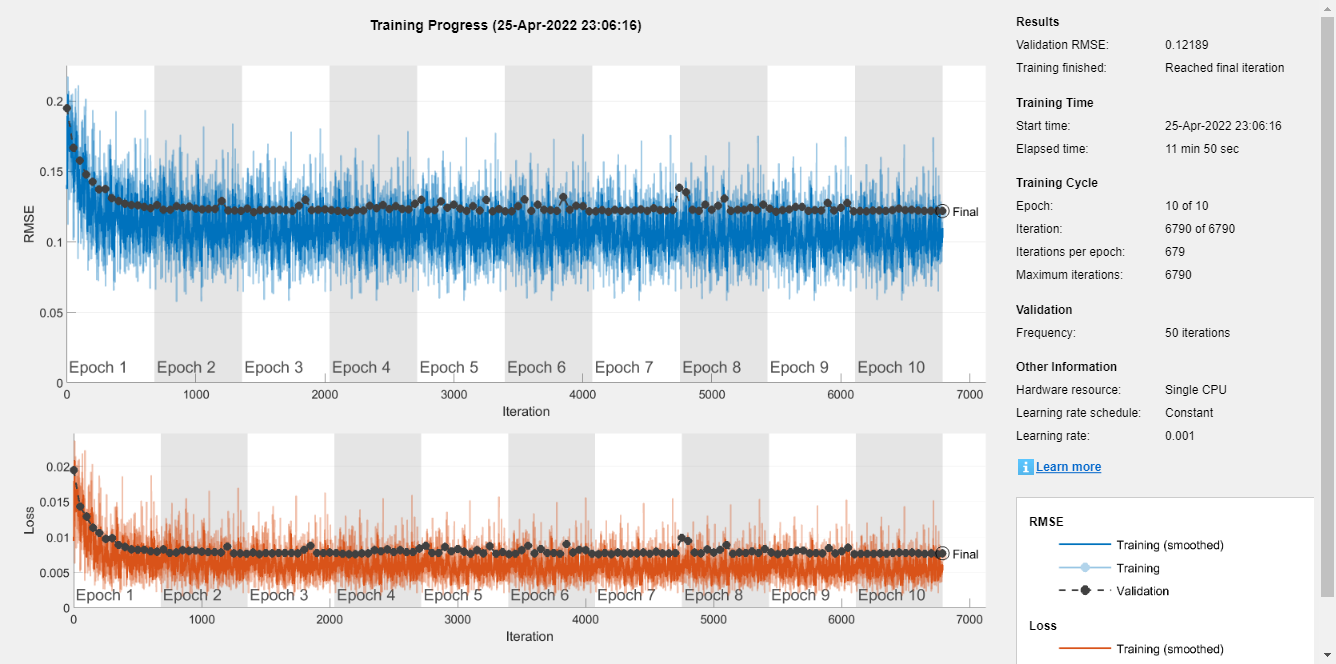

cc_input_size = 20;
numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(cc_input_size)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

layersLSTM2 = [ ...
    sequenceInputLayer(cc_input_size)
    lstmLayer(numHiddenUnits)
    dropoutLayer(0.2)
    lstmLayer(numHiddenUnits)
    dropoutLayer(0.2)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(xnorm', 1)';
cellyB = num2cell(ynorm);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',epoc_count, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

tic
netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);

toc 

Elapsed time is 733.099408 seconds.


Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:10 |         0.27 |         0.28 |       0.0374 |       0.0398 |          0.0010 |
|       1 |          50 |       00:00:17 |         0.17 |         0.19 |       0.0136 |       0.0182 |          0.0010 |
|       1 |         100 |       00:00:24 |         0.14 |         0.18 |       0.0093 |       0.0169 |          0.0010 |
|       1 |         150 |       00:00:31 |         0.17 |         0.16 |       0.0152 |       0.0136 |          0.0010 |
|       

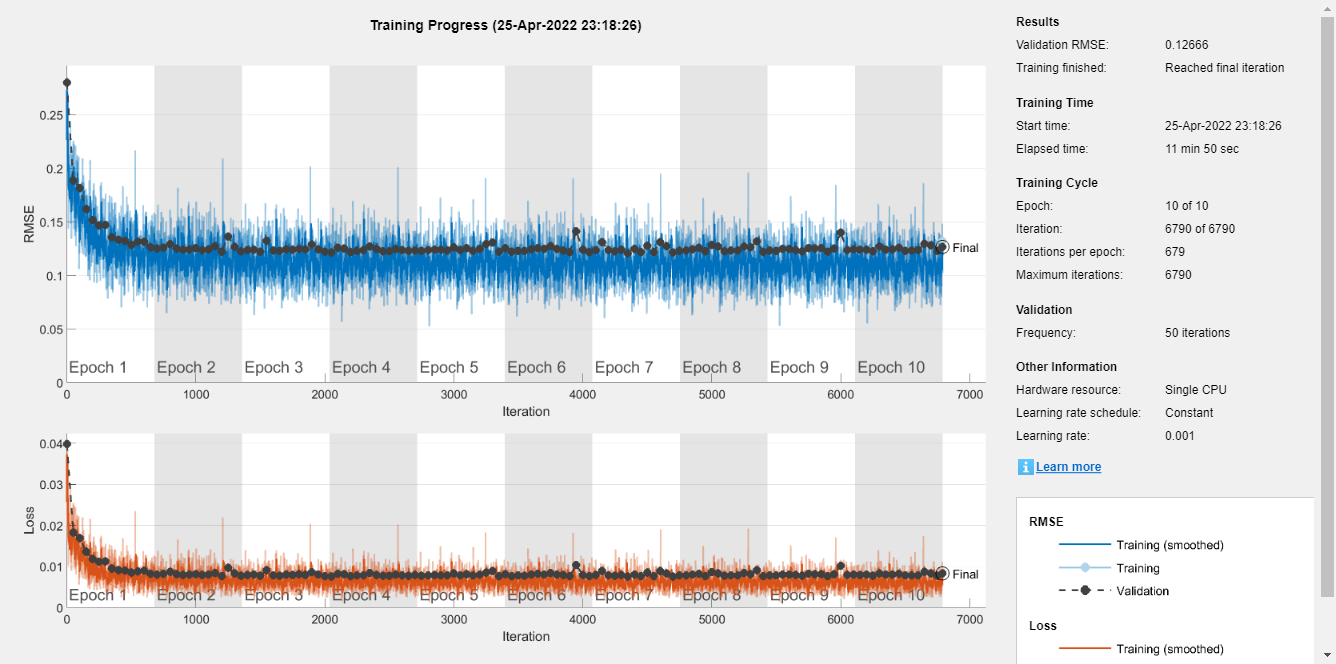


tic
netLSTM2 = trainNetwork(traincellx, traincellyB, layersLSTM2, options);

toc

Elapsed time is 725.950365 seconds.



pLSTM = cell2mat(predict(netLSTM, num2cell(xnorm(tr.testInd, :)', 1)));
pLSTM2 = cell2mat(predict(netLSTM2, num2cell(xnorm(tr.testInd, :)', 1)));
ytest = ynorm(tr.testInd, :)*yrate + ymin;
pLSTM_hat = pLSTM * yrate + ymin;
pLSTM2_hat = pLSTM2 * yrate + ymin;
rmse_pLSTM_hat = sqrt(mean(( ytest' - pLSTM_hat' ).^2))

rmse_pLSTM_hat = single
128.6903

rmse_pLSTM2_hat = sqrt(mean(( ytest' - pLSTM_hat' ).^2))

rmse_pLSTM2_hat = single
128.6903

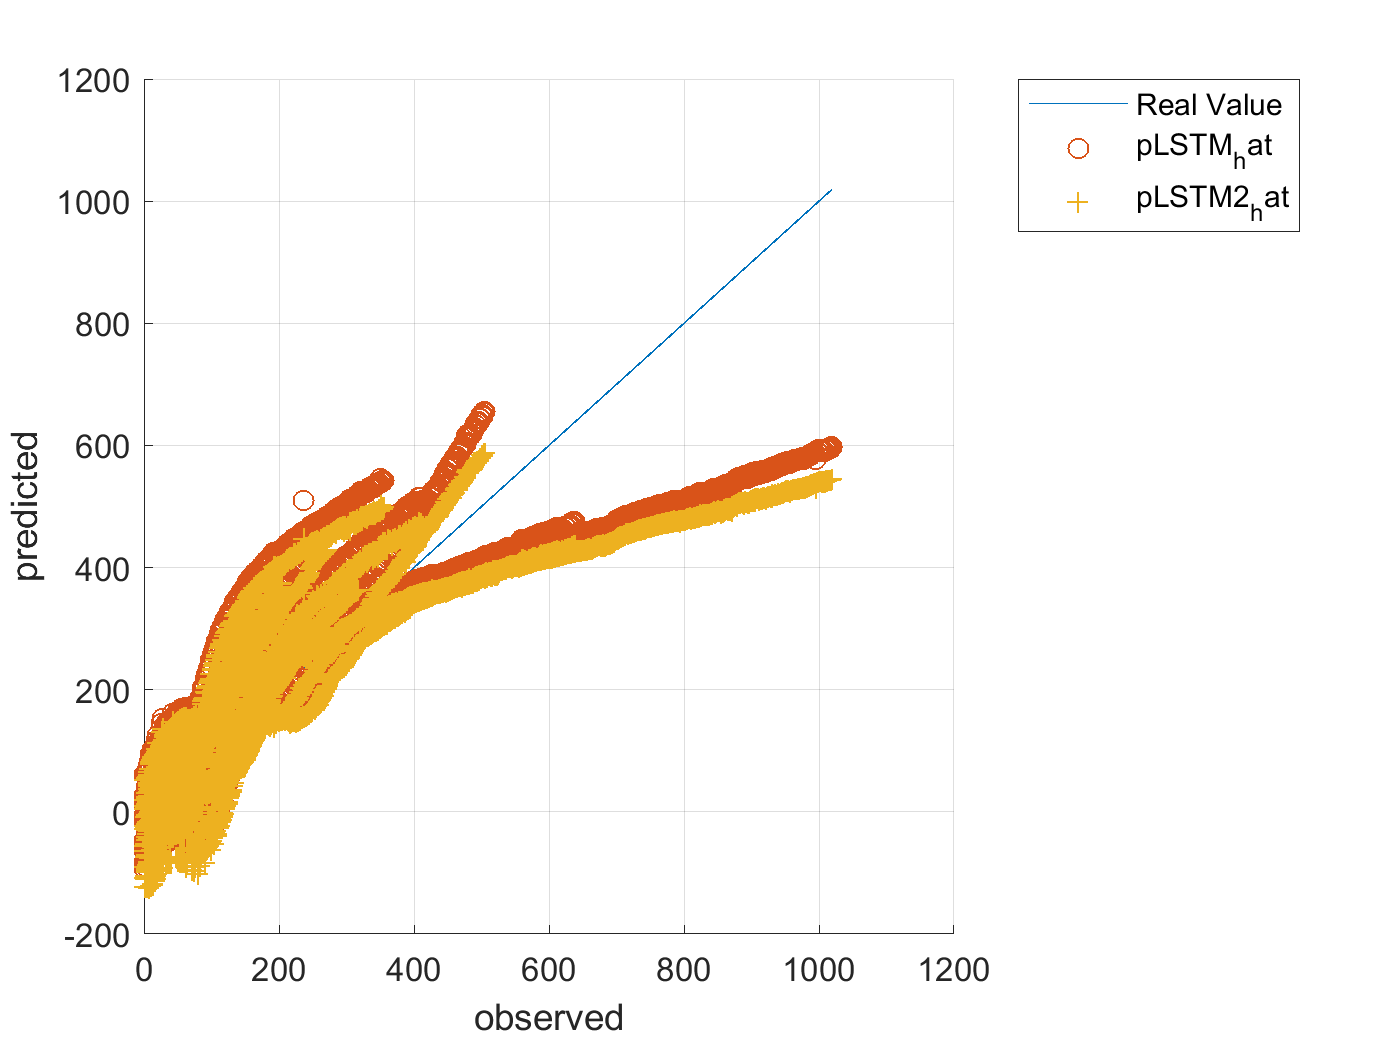



figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pLSTM_hat,'o')
plot(ytest,pLSTM2_hat,'+')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pLSTM_hat', ...
        'pLSTM2_hat','Location','northeastoutside')


save('ryan3_model_chargeCurrent_RUL1.mat','netLSTM' ,'-append')
save('ryan3_model_chargeCurrent_RUL1.mat','netLSTM2' ,'-append')

pLSTM_self = cell2mat(predict(netLSTM, num2cell(xnorm([tr.trainInd tr.valInd], :)', 1)));
pLSTM2_self = cell2mat(predict(netLSTM2, num2cell(xnorm([tr.trainInd tr.valInd], :)', 1)));
ytrain_self = ynorm([tr.trainInd tr.valInd], :)*yrate + ymin;
pLSTM_self = pLSTM_self * yrate + ymin;
pLSTM2_self = pLSTM2_self * yrate + ymin;
rmse_pLSTM_self_hat = sqrt(mean(( ytrain_self' - pLSTM_self' ).^2))

rmse_pLSTM_self_hat = single
125.4615

rmse_pLSTM2_self_hat = sqrt(mean(( ytrain_self' - pLSTM2_self' ).^2))

rmse_pLSTM2_self_hat = single
129.6892

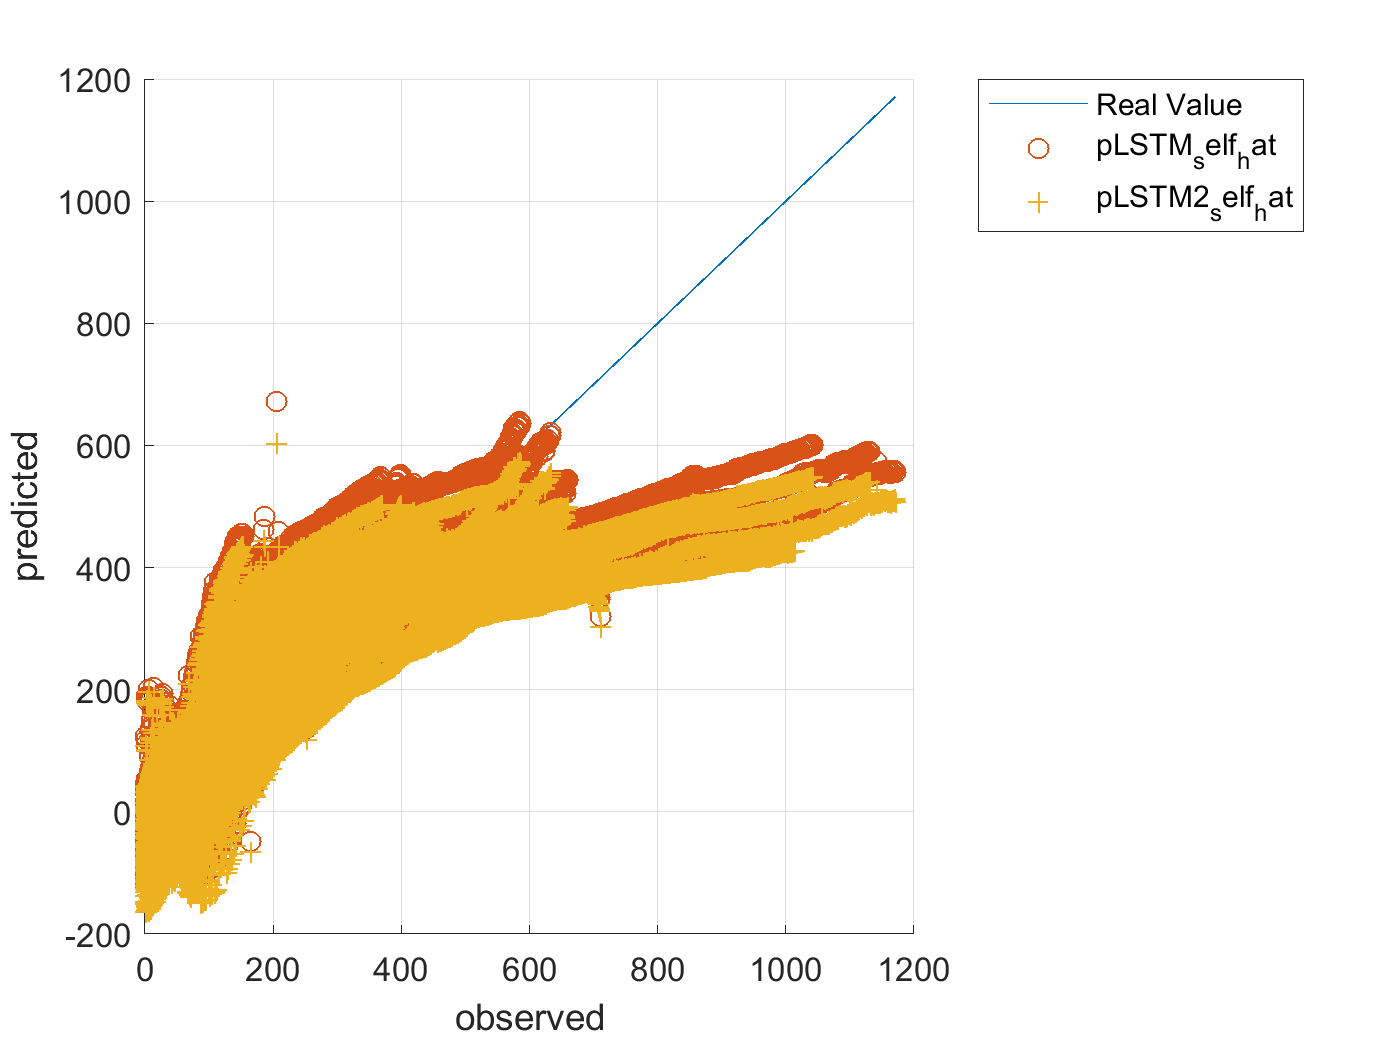


figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pLSTM_self,'o')
plot(ytrain_self,pLSTM2_self,'+')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pLSTM_self_hat', ...
        'pLSTM2_self_hat','Location','northeastoutside')